# Receptor annotation pipeline and its application

## Section 5: Development of a region-based identification method for annotation of the FpvA receptors

Short summary: In this section, based on the reference fpvA and fpvB sequences, we developed the pipline for identifying FpvA receptors from genomes.

clc;
clear;
%%%%%%%%%
% check if the current folder is correct:
currentpath=pwd;if sum(currentpath=='\')>sum(currentpath=='/'), sepstr='\';else ; sepstr='/';end
currentpathlist=(strsplit(currentpath,sepstr));
if ~strcmp(currentpathlist{end},'Figure5_6_receper_part')
    error('Not in the right path. Please switch to the path of code/code/Figure5_6_receper_part/, and make sure it contains three subfolders: "data","hmms", and "Tools". ')
end


This step loads the reference fpvA and fpvB sequences from the data folder. 

Data files: 

    "reference_FpvA.fasta": 21 fpvA sequences from [The Pseudomonas Genome Database ](https://www.pseudomonas.com/)

    "reference_FpvB.fasta": 6 fpvA sequences from [The Pseudomonas Genome Database ](https://www.pseudomonas.com/)

    "othersids_heads.fasta": Other TONB-dependent siderophores receptors that are not fpvA nor fpvB. 

Together, data from these files constitutes the variable "refreceptors" with 35 siderophore receptors, where we learn the characteristics of fpvA receptors. We removed the receptors under the name of "pseudobactin" (as it's the other name of pyoverdine), and not in the length range of [750,850] aa.

%%%%%%load reference%%%%%%
datapath='./data/';
% the first is PAO1, the standard seq
[fpvA_heads,fpvA_seqs]=fastaread([datapath,'reference_FpvA.fasta']);
fpvA_heads=fpvA_heads';
fpvA_seqs=fpvA_seqs';

[fpvB_heads,fpvB_seqs]=fastaread([datapath,'reference_FpvB.fasta']);
fpvB_heads=fpvB_heads';
fpvB_seqs=fpvB_seqs';

[othersids_heads,othersids_seqs]=fastaread([datapath,'sid18_receptor.fasta']);
othersids_heads=othersids_heads';
othersids_seqs=othersids_seqs';

refreceptors=[];
refreceptors.seqs=[fpvA_seqs;fpvB_seqs;othersids_seqs];
refreceptors.names=[fpvA_heads;fpvB_heads;othersids_heads];
refreceptors.num=length(refreceptors.seqs);
refreceptors.len=zeros(refreceptors.num,1);
for i=1:refreceptors.num
    refreceptors.len(i)=length(refreceptors.seqs{i});
end
% get the short name
refreceptors.shortnames=[];
refreceptors.typeid=[];
for i=1:refreceptors.num
    longname=refreceptors.names{i};
    if ~(i>(length(fpvA_heads)+length(fpvB_heads)))
        strlist=strsplit(longname,'|');
        if i>length(fpvA_heads)%fpvB
            shortname=['fpvB |',strlist{end}];
            refreceptors.typeid(i,1)=2;
        else
            shortname=['fpvA |',strlist{end}];
            refreceptors.typeid(i,1)=1;
        end
    else
        strlist=strsplit(longname,' ');
        shortname=strlist{1};
        refreceptors.typeid(i,1)=0;
    end
    shortname(shortname=='_')='-';
    refreceptors.shortnames{i,1}=shortname;
end

refreceptors.seqlenrange=[750,850];
refreceptors.tocheckseq=find(~strcmp('pseudobactin',refreceptors.shortnames) & ~(refreceptors.len<refreceptors.seqlenrange(1)) & ~(refreceptors.len>refreceptors.seqlenrange(2)));

Align the 35 reference receptors, calculate their distances, and perform hierarchical clustering

refreceptors.mulalign_tocheck=multialign(refreceptors.seqs(refreceptors.tocheckseq));
[ref_CSeq, ref_Score] = seqconsensus(refreceptors.mulalign_tocheck);
refreceptors.gapfreq=sum(refreceptors.mulalign_tocheck=='-')/size(refreceptors.mulalign_tocheck,1);
refreceptors.distm_tocheck=squareform(seqpdist(refreceptors.mulalign_tocheck,'Method','p-distance'));
linkm=linkage(refreceptors.distm_tocheck,'complete');
refreceptors.optleaforder=optimalleaforder(linkm,refreceptors.distm_tocheck);

Load three standard receptor domains (STN, Plug, and TonBDR) in TONB-dependent siderophore receptors. The information of them were stored in the varible "recdomain_hmms"

STNhmm=pfamhmmread('./hmms/STN.hmm');
Plughmm=pfamhmmread('./hmms/Plug.hmm');
TonBhmm = pfamhmmread('./hmms/TonB_dep_Rec.hmm');

recdomain_hmms=[];
recdomain_hmms.models={STNhmm,Plughmm,TonBhmm};
recdomain_hmms.modelnames={'STN','Plug','TonB'};
recdomain_hmms.num=length(recdomain_hmms.models);


Annotate the first receptor in the reference set, which is fpvA from strain PAO1, based on canonical insights gleaned from prior research:

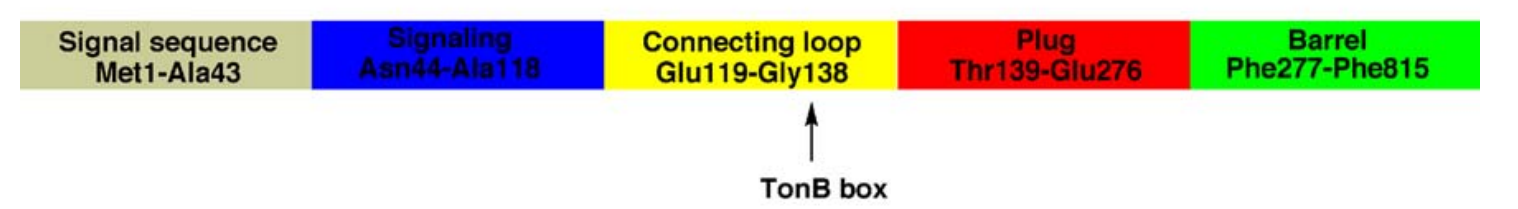

Citation: Schalk, Isabelle J., Iain L. Lamont, and David Cobessi. "Structure–function relationships in the bifunctional ferrisiderophore FpvA receptor from Pseudomonas aeruginosa." *Biometals* 22.4 (2009): 671-678.

refreceptors.pao1_loc=1;
refreceptors.pao1_ses=[1,43;
    44,118;
    119,138;
    139,276;
    277,815];
refreceptors.annostr={'Signaling Sequence';
    'Signaling';
    'Connecting loop';
    'Plug';
    'Barrel'};

refreceptors.color=[0.5,0.5,0.5;
    0,0,1;
    1,1,0;
    1,0,0;
    0,1,0];

Annotate known subtypes of pyoverdines (also referred to as pseudobactins) in the reference set.

cite: Ambrosi, Cecilia, Livia Leoni, and Paolo Visca. "Different responses of pyoverdine genes to autoinduction in Pseudomonas aeruginosa and the group Pseudomonas fluorescens-Pseudomonas putida." *Applied and environmental microbiology* 68.8 (2002): 4122-4126.

refreceptors.rectype=nan*zeros(refreceptors.num,1);
refreceptors.rectype([1     2     7    10    16    22])=1;% PAO1
refreceptors.rectype(18)=2;% Pseudomonas aeruginosa M18|PAM18_2643
refreceptors.rectype(5)=3;%Pseudomonas aeruginosa LESB58|PALES_28981

## Figure 5a

Display the hierarchically clustered sequence distances of the 35 reference sequences.

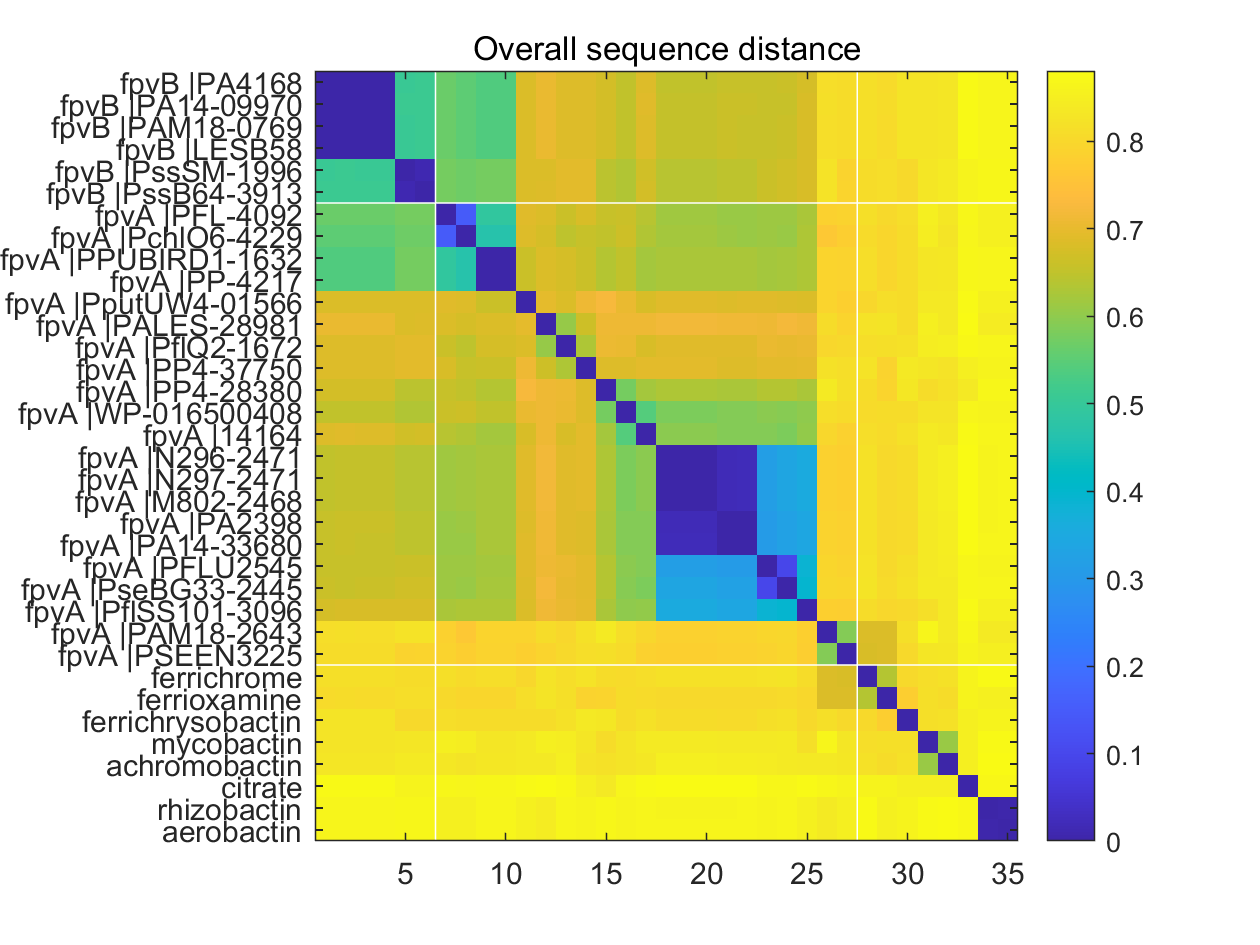

figure;
imagesc(refreceptors.distm_tocheck(refreceptors.optleaforder,refreceptors.optleaforder));
colorbar;
yticks(1:length(refreceptors.tocheckseq))
yticklabels(refreceptors.shortnames(refreceptors.tocheckseq(refreceptors.optleaforder)));
title('Overall sequence distance')
hold on;
    plot([0,length(refreceptors.tocheckseq)+1],(sum(refreceptors.typeid(refreceptors.tocheckseq(refreceptors.optleaforder))==2)+0.5)*[1,1],'w')
    plot([0,length(refreceptors.tocheckseq)+1],(sum(refreceptors.typeid(refreceptors.tocheckseq(refreceptors.optleaforder))>0)+0.5)*[1,1],'w');
    plot((sum(refreceptors.typeid(refreceptors.tocheckseq(refreceptors.optleaforder))==2)+0.5)*[1,1],[0,length(refreceptors.tocheckseq)+1],'w')
    plot((sum(refreceptors.typeid(refreceptors.tocheckseq(refreceptors.optleaforder))>0)+0.5)*[1,1],[0,length(refreceptors.tocheckseq)+1],'w');

% conservation of the sequences being selected
fprintf('%d fpvAs, %d fpvBs, %d others\n',sum(refreceptors.typeid(refreceptors.tocheckseq)==1),sum(refreceptors.typeid(refreceptors.tocheckseq)==2),sum(refreceptors.typeid(refreceptors.tocheckseq)==0));

21 fpvAs, 6 fpvBs, 8 others


## Figure 5b

The pHMM scores of the three standard receptor domains (STN, Plug, and TonBDR) vary across the 35 reference  sequences

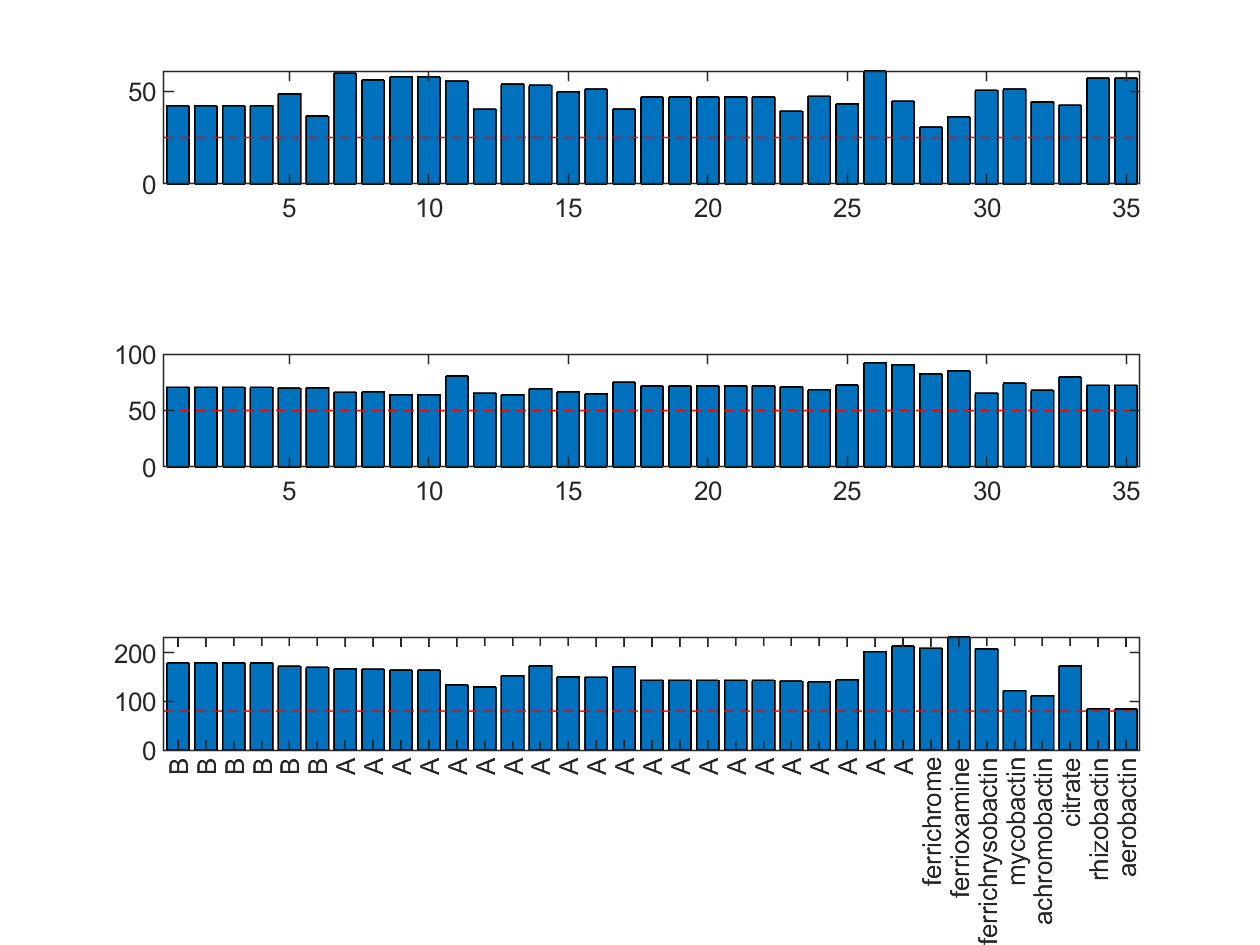

receptor_hmm_scorem=size(3,size(refreceptors.mulalign_tocheck,1));
receptor_hmm_seqs=[];
receptor_hmm_se=size(3,length(refreceptors.tocheckseq),2);
mulalign_countisdomain=zeros(3,size(refreceptors.mulalign_tocheck,2));
for i=1:length(refreceptors.tocheckseq)
    seq=refreceptors.seqs{refreceptors.tocheckseq(i)};
    seq(aa2int(seq)>22)='-'; 
    mul_thisseq_nogap=(refreceptors.mulalign_tocheck(i,:)~='-');
    nongapcum=cumsum(mul_thisseq_nogap);
    for m=1:recdomain_hmms.num
        [phaligncore, alignment, pointer] = hmmprofalign(recdomain_hmms.models{m}, seq);
        receptor_hmm_scorem(m,i)=phaligncore;
        receptor_hmm_seqs{m,i}=alignment;
        receptor_hmm_se(m,i,1)=min(pointer);
        receptor_hmm_se(m,i,2)=max(pointer);  
        startponmul=find(nongapcum==min(pointer), 1 );
        stopponmul=find(nongapcum==max(pointer), 1 );
        mulalign_countisdomain(m,startponmul:stopponmul)=mulalign_countisdomain(m,startponmul:stopponmul)+1;
    end
end
shortername=[];
for i=1:length(refreceptors.shortnames)
    if refreceptors.typeid(i)==1
        shortername{i,1}='A';
    elseif refreceptors.typeid(i)==2
        shortername{i,1}='B';    
    else
        shortername{i,1}=refreceptors.shortnames{i};
    end
end
figure;
thresholds_list=[25,50,80];
for m=1:recdomain_hmms.num
    subplot(recdomain_hmms.num,1,m);
    bar(receptor_hmm_scorem(m,refreceptors.optleaforder));
    hold on;
    plot([0.5,length(refreceptors.optleaforder)+1.5],thresholds_list(m)*[1,1],'r --')
xlim([0.5,length(refreceptors.optleaforder)+0.5])
end
xticks(1:length(refreceptors.tocheckseq))
xticklabels(shortername(refreceptors.tocheckseq(refreceptors.optleaforder)));

## Figure 5c

Analysis of the multi-alignment of the 35 reference sequences.

Height represents the degree of conservation in each residue.

Color represents how well the region distinguishes fpvA with the rest of the receptors. Two regions that are most distinguishable between fpvA and the others are termed "R1" and "R2."

The HMM models formed by sequences in these two regions were recorded in the variable  "fpvA_pfammodels"

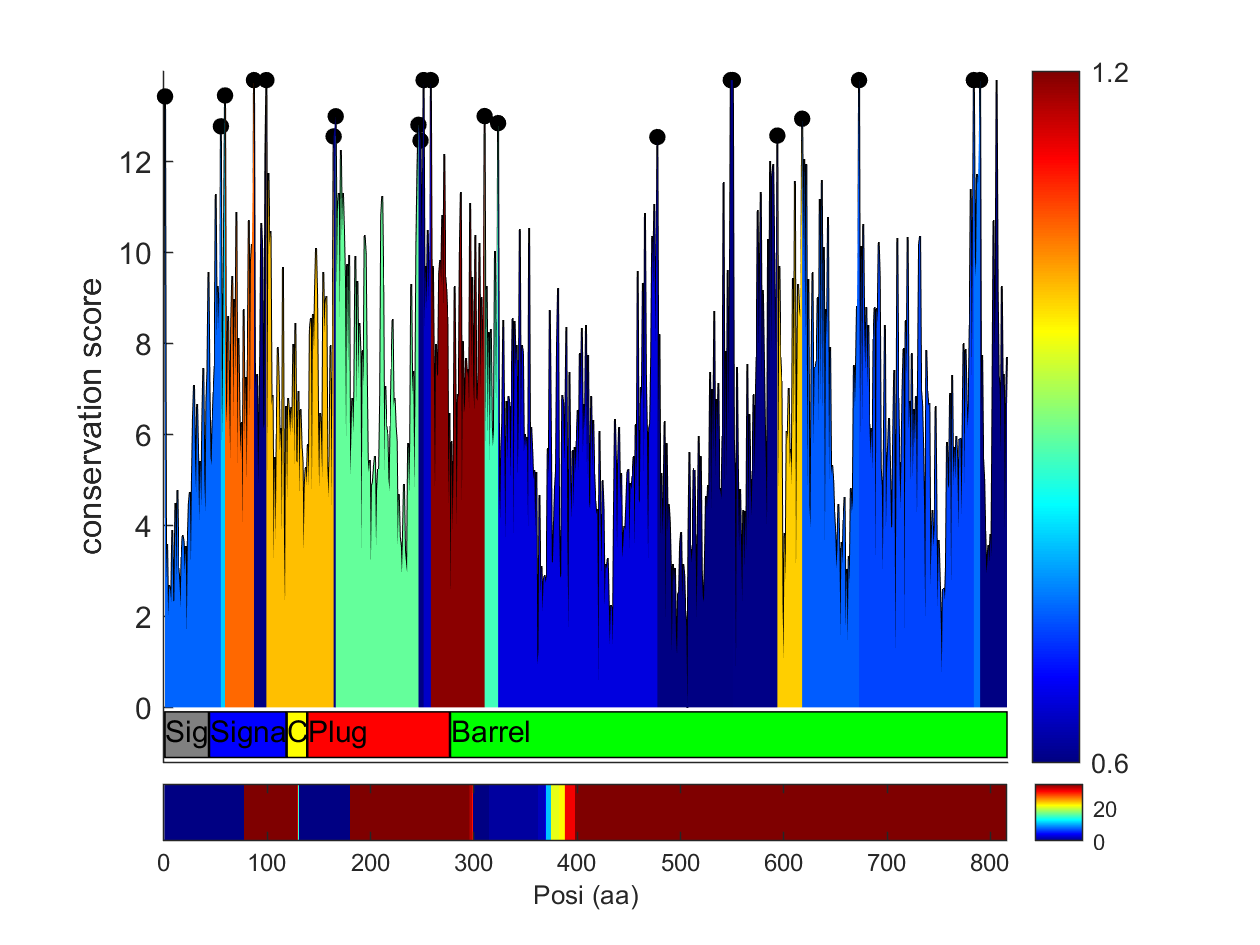

% conservation and fragmentation of the refseq 
threshhold_conservescore=0.9;
conservescore=(max(ref_Score)-ref_Score).*(1-refreceptors.gapfreq);
% does the seq exist in the first sequence(PAO fpv1);
existinPao1=find(refreceptors.mulalign_tocheck(1,:)~='-');
templist=find(conservescore>threshhold_conservescore*max(conservescore));
seperateposi=templist(1);
for i=2:(length(templist)-1)
    if templist(i)-templist(i-1)>0
        seperateposi(end+1)=templist(i);
    end
end
seperateposi=unique([1,seperateposi,length(conservescore)]);
% locate the position in PAO1
mullocinpao1=cumsum(refreceptors.mulalign_tocheck(1,:)~='-');
sep_se=[seperateposi(1:(end-1))',seperateposi(2:end)'-1];
sep_se(end,2)=length(conservescore);
sepscore_list=zeros(size(sep_se,1),1);
mulisAlist=find(refreceptors.typeid(refreceptors.tocheckseq)==1); 
otherlist=find(refreceptors.typeid(refreceptors.tocheckseq)~=1);
for i=1:size(sep_se,1)
    sp=sep_se(i,1);
    ep=sep_se(i,2);
    scorem=squareform(seqpdist(refreceptors.mulalign_tocheck(:,sp:ep),'Method','p-distance'));
    dist_A_A=(scorem(mulisAlist,mulisAlist));
    dist_A_other=scorem(mulisAlist,otherlist);
    sepscore_A=(mean(dist_A_other(:))-mean(dist_A_A(:)))/std(dist_A_A(:));
    sepscore_list(i)=sepscore_A;
end

figure;
subplotnum=10;
subplot(subplotnum,1,1:(subplotnum-1))
hold on;
xlist=1:length(existinPao1);
plot(xlist,conservescore(existinPao1),'k');
scatter(mullocinpao1(seperateposi),conservescore(seperateposi),30,'k','filled');
colortable=colormap(jet);
mincolorv=0.6;maxcolorv=1.2;
for i=1:size(sep_se,1)
    sp=sep_se(i,1);
    ep=sep_se(i,2);
    splist=intersect(sp:ep,existinPao1);
    if i~=size(sep_se,1)
        splist(end)=splist(end)+1;
    end
    sepscore_A=sepscore_list(i);
    colorid=min(size(colortable,1),max(1,round(size(colortable,1)*(sepscore_A-mincolorv)/(maxcolorv-mincolorv))));
    fh=fill(mullocinpao1([splist(1),splist,splist(end)]),[0,conservescore(splist),0],colortable(colorid,:));
    fh.LineStyle='none';
end
% mark the poisition for domains
height=1;
for i=1:size(refreceptors.pao1_ses)
    startp=refreceptors.pao1_ses(i,1);
    stopp=refreceptors.pao1_ses(i,2);
    colorcode=refreceptors.color(i,:);
    annostr=refreceptors.annostr{i};
    patch([startp,stopp,stopp,startp],-0.1+[-1,-1,0,0]*height,colorcode);
    text(startp,-0.5,annostr)
end
ch=colorbar;
ch.Ticks=[0,1];
ch.TickLabels= strsplit(sprintf('%0.1f ',[mincolorv,maxcolorv]));
xlim([0,length(existinPao1)+1])
ylim([-1.2,max(conservescore)+0.2])
xticks([])
ylabel('conservation score');
subplot(subplotnum,1,subplotnum)
% mark the three domain annotation
barheight=sum(mulalign_countisdomain,1);
imagesc(1:length(barheight),-1.6*ones(size(barheight)),barheight)
xlim([0,length(existinPao1)+1])
yticks([])
xlabel('Posi (aa)')
colorbar

## Figure 5d

The two regions with the highest FpvA identification scores R1(dark red) and 408 R2 (orange) were mapped to the FpvA crystal structure of  PAO1 conjugated with pyoverdine (PDB 2IAH) by PyMOL. 

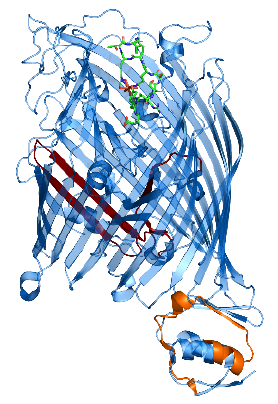

## Figure 5e-f

Heatmap showing the hierarchically clustered sequence distances of 35 reference  receptors 411 based the R1 sequence region, and the R2 sequence region

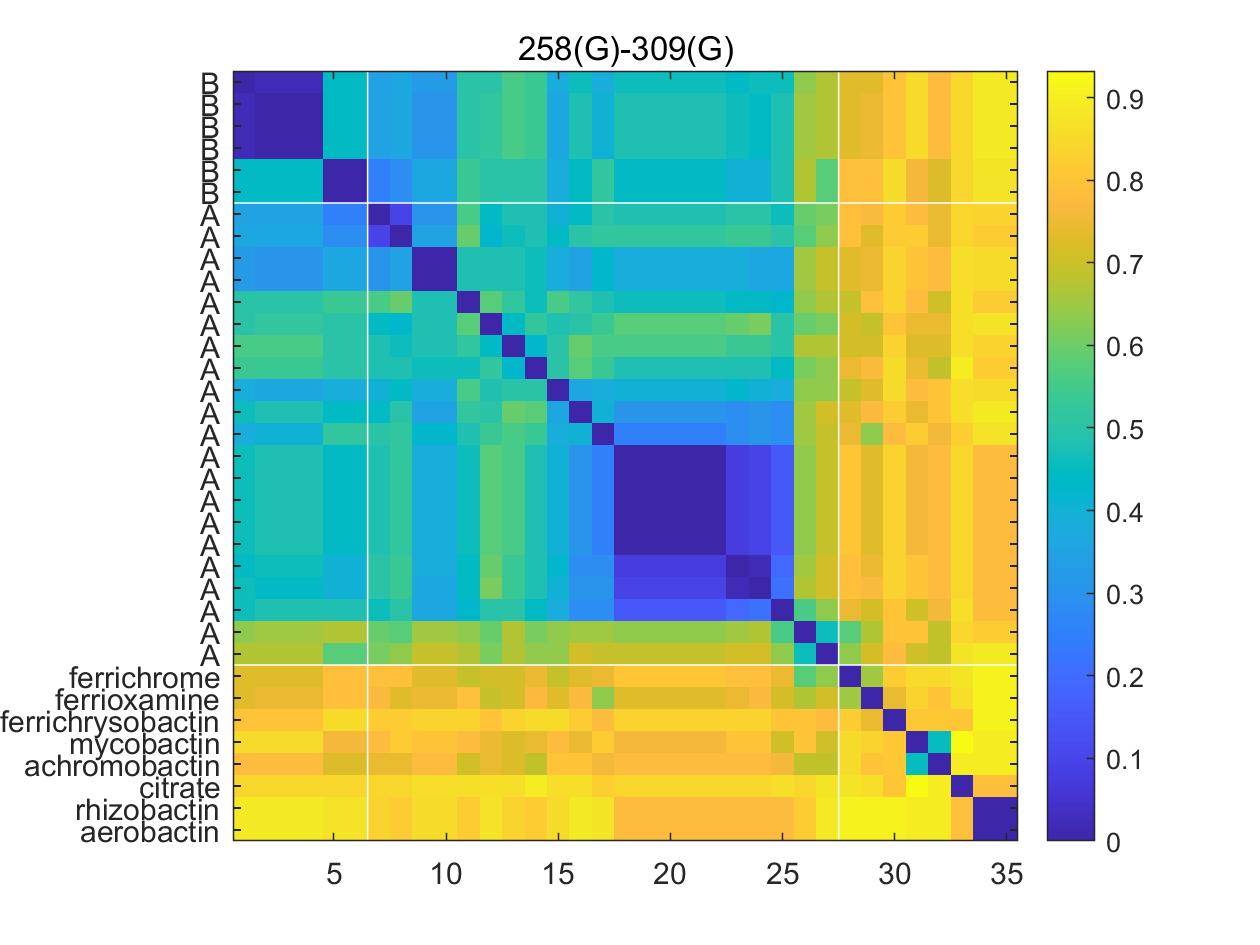

ans =     0.5469         0         0


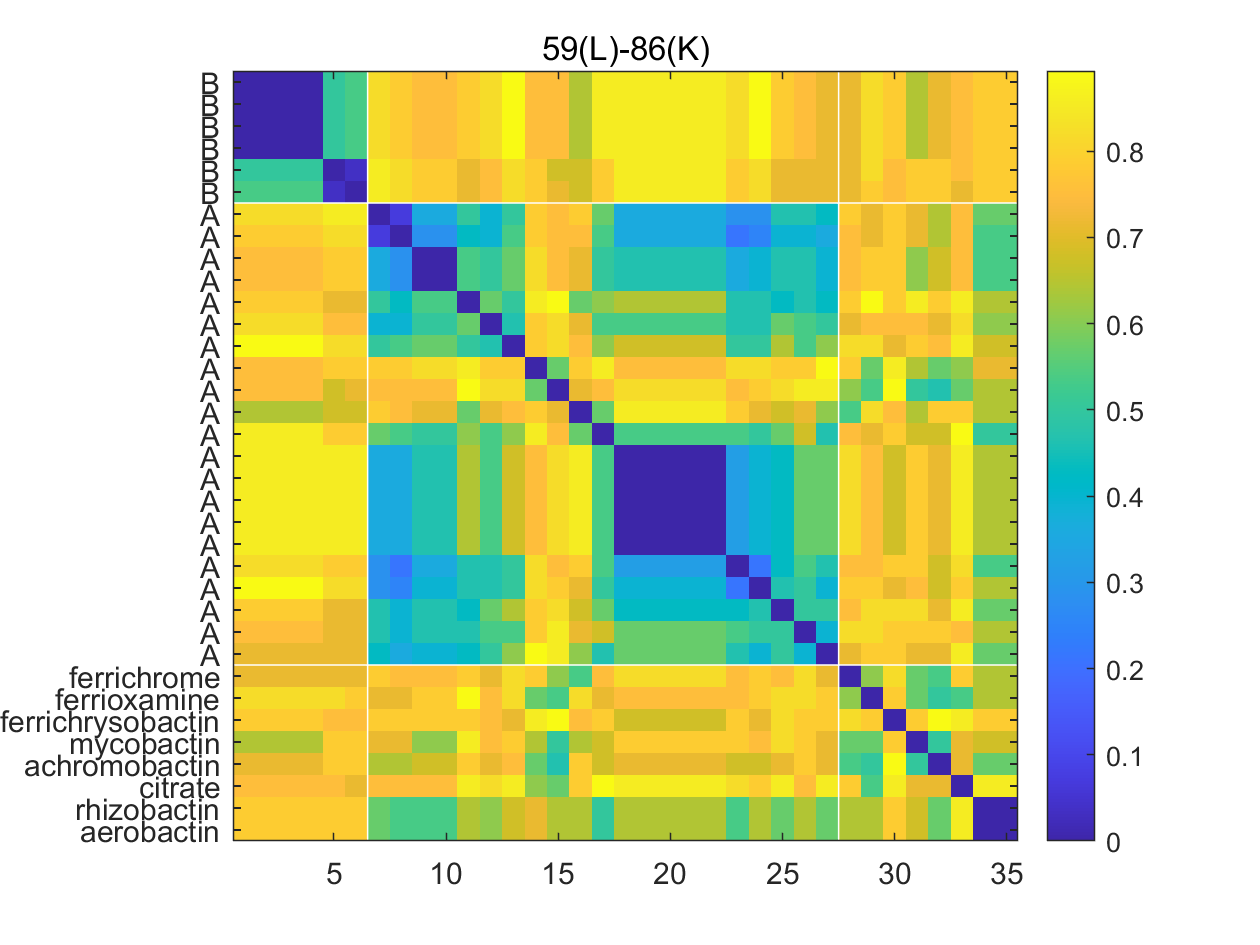

ans =     1.0000    0.4062         0



select_topregnum=2;gapthresh=0.5;

%raw=load('./output/firstversion_fpvApfammodel.mat');% saved for last time

[~,order]=sort(sepscore_list,'descend');

fpvA_pfammodels=[];
fpvA_pfammodels.num=0;

sptables=sep_se(order(1:select_topregnum),1:2);
recordscorem=[];
for i=1:size(sptables)
    
    sp=sptables(i,1);
    ep=sptables(i,2);
    
    mulalign=refreceptors.mulalign_tocheck(:,sp:ep);
    gapfreq=sum(mulalign=='-',1)/size(mulalign,1);
    titlestr=sprintf('%d(%s)-%d(%s)',mullocinpao1(sp),refreceptors.mulalign_tocheck(1,sp),mullocinpao1(ep),refreceptors.mulalign_tocheck(1,ep));

    
    scorem=squareform(seqpdist(mulalign,'Method','p-distance'));
    recordscorem(:,:,i)=scorem;
   
    figure;
    imagesc(scorem(refreceptors.optleaforder,refreceptors.optleaforder));
    colorbar
    title(titlestr);
    yticks(1:length(refreceptors.tocheckseq))
    yticklabels(shortername(refreceptors.tocheckseq(refreceptors.optleaforder)));
    
    hold on;
    plot([0,size(scorem,1)+1],(sum(refreceptors.typeid(refreceptors.tocheckseq(refreceptors.optleaforder))==2)+0.5)*[1,1],'w')
    plot([0,size(scorem,1)+1],(sum(refreceptors.typeid(refreceptors.tocheckseq(refreceptors.optleaforder))>0)+0.5)*[1,1],'w');
    plot((sum(refreceptors.typeid(refreceptors.tocheckseq(refreceptors.optleaforder))==2)+0.5)*[1,1],[0,size(scorem,1)+1],'w')
    plot((sum(refreceptors.typeid(refreceptors.tocheckseq(refreceptors.optleaforder))>0)+0.5)*[1,1],[0,size(scorem,1)+1],'w');
 
    %%%%%%%%%%%%%%% get a model
    touselist=find(refreceptors.typeid(refreceptors.tocheckseq)==1);
    if i==2
         touselist=find((refreceptors.typeid==2));
    end
    firstmodel = hmmprofstruct(sum(gapfreq<gapthresh));
    fpvA_pfammodels.num=fpvA_pfammodels.num+1;
    fpvA_pfammodels.models{fpvA_pfammodels.num}= hmmprofestimate(firstmodel, mulalign(touselist,:));
    fpvA_pfammodels.fpv_ABother=refreceptors.typeid(refreceptors.tocheckseq);
    fpvA_pfammodels.mulalign{fpvA_pfammodels.num}=mulalign;

    
    sepscore_A=sepscore_list(order(i));
    colorid=min(size(colortable,1),max(1,round(size(colortable,1)*(sepscore_A-mincolorv)/(maxcolorv-mincolorv))));
    
    colortable(colorid,:)
end

## Figure 5g

The pHMM scores of regions R1 and R2 for the 35 siderophore reference receptors are contrasted against each other, yielding a clear separation between FpvA, FpvB and other receptors. 

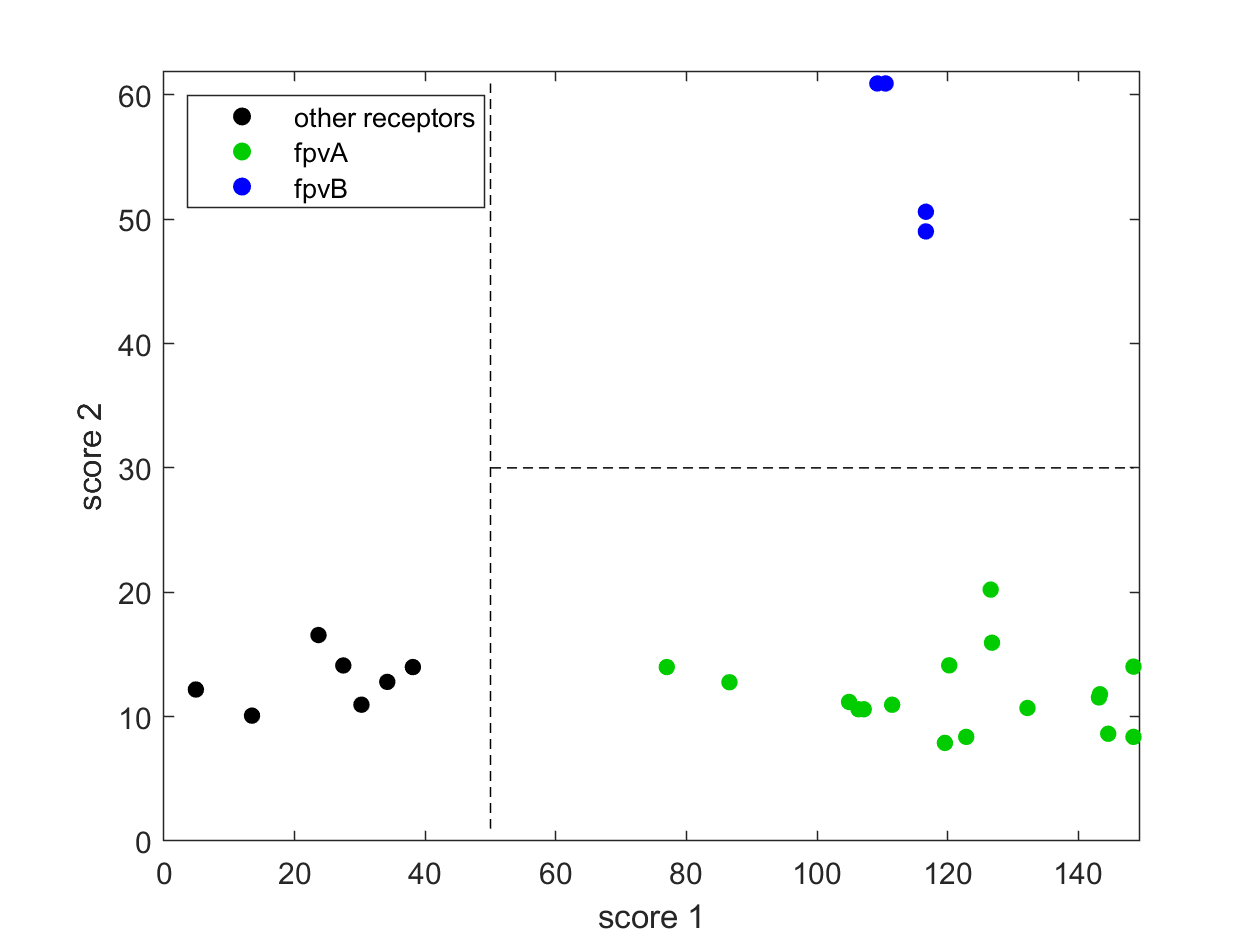

fpvA_hmm_scorem=size(fpvA_pfammodels.num,size(refreceptors.mulalign_tocheck,1));
fpvA_hmm_seqs=[];
fpvA_hmm_se=size(3,size(refreceptors.mulalign_tocheck,1),2);
pickthresh=[50,30];
for i=1:size(refreceptors.mulalign_tocheck,1)
    seq=refreceptors.seqs{refreceptors.tocheckseq(i)};
    seq(aa2int(seq)>22)='-';
    
   
    for m=1:fpvA_pfammodels.num
        [phaligncore, alignment, pointer] = hmmprofalign(fpvA_pfammodels.models{m}, seq);

        fpvA_hmm_scorem(m,i)=phaligncore;
        fpvA_hmm_seqs{m,i}=alignment;
        fpvA_hmm_se(m,i,1)=min(pointer);
        fpvA_hmm_se(m,i,2)=max(pointer);
    end
end

figure;hold on;
colorcodes=[0,0,0;
    0,0.8,0;
    0,0,1;];
lh=[];
for i=1:3
    list=find(refreceptors.typeid(refreceptors.tocheckseq)==(i-1));
    lh(i)=scatter(fpvA_hmm_scorem(1,list),fpvA_hmm_scorem(2,list),30,colorcodes(i,:),'filled');
end
plot(pickthresh(1)*[1,1],[1,max(fpvA_hmm_scorem(2,:))],'-- k')
plot([pickthresh(1),max(fpvA_hmm_scorem(1,:))],pickthresh(2)*[1,1],'-- k')
ylim([0,max(fpvA_hmm_scorem(2,:))+1])
xlim([0,max(fpvA_hmm_scorem(1,:))+1])
xlabel('score 1')
ylabel('score 2');
box on
legend(lh,{'other receptors','fpvA','fpvB'},'Location','northwest')

## Figure 5h

A sequence-region-based identification pipeline for annotating FpvA receptors

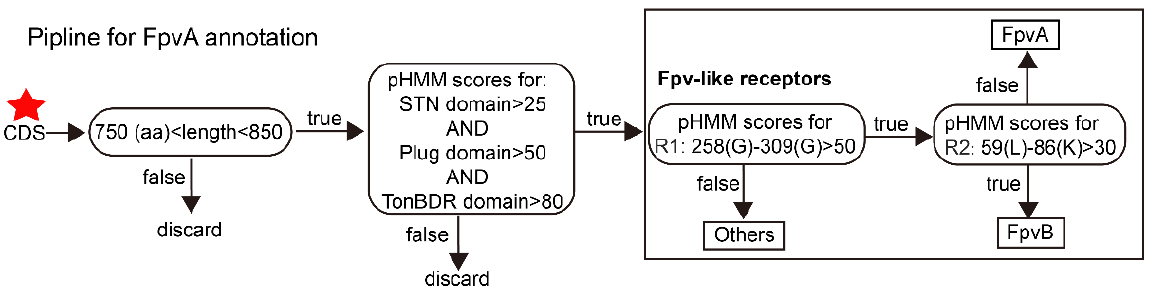

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Section 6: Application of the receptor annotation pipeline to the full dataset

According to the figure in Figure 5h, applying length fildering and STN, Plug, and TonBDR domain filtering to all genes in 1961 Psudomonas strains, we obtained 14609 Fpv-like receptors, stored in the variable "pickedrec." 

Then, appyling the HMM models of R1 and R2 stored in "fpvA_pfammodels" to all 14609 Fpv-like receptors, we obtained 4547 fpvA receptors, stored in the vaiable "pickedrec_fpva"


load ./data/pickedrec.mat;
load ./data/pickedrec_fpva.mat;
load ./data/taxt.mat;
load ./data/mindist.mat;
load ./data/Feature_rec.mat;
load ./data/fpvA_hmm_scorem.mat;
addpath('./Tools/');
addpath('./Tools/cbrewer/');

## Figure 6a

The R1 pHMM scores and the R2 pHMM scores for the 14301 Fpv-like receptors. 

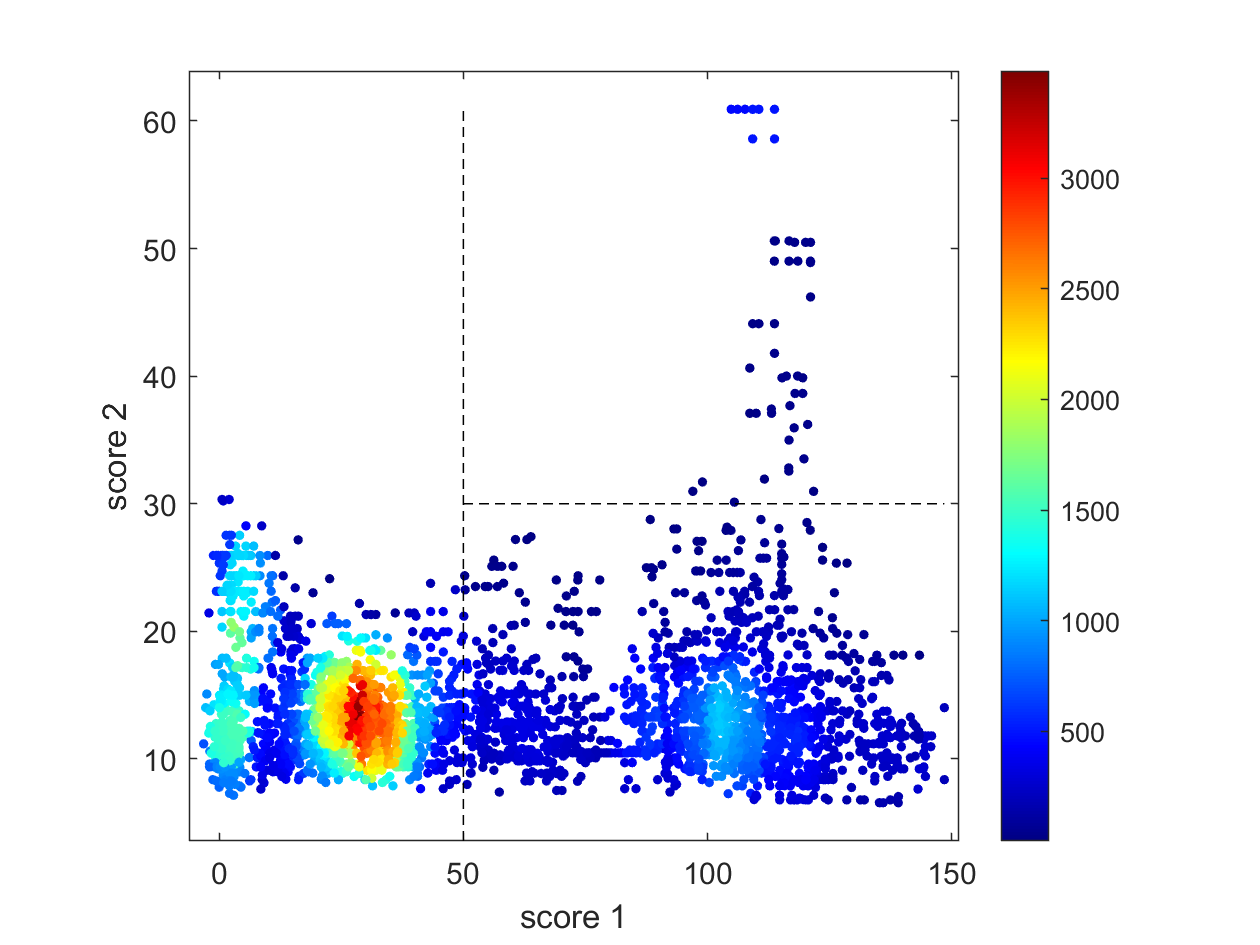

figure;
colormap(jet)
markersize=10;
X = [pickedrec.fpvA_hmm_scorem(309:end,1),pickedrec.fpvA_hmm_scorem(309:end,2)];
D = pdist(X);
Dthresh=0.04*max(D(:));
degX=sum(squareform(D)<Dthresh);

scatter(X(:,1),X(:,2),markersize,degX,'filled');
colorbar
hold on;
plot(pickthresh(1)*[1,1],[1,max(pickedrec.fpvA_hmm_scorem(309:end,2))],'-- k')
plot([pickthresh(1),max(pickedrec.fpvA_hmm_scorem(309:end,1))],pickthresh(2)*[1,1],'-- k')
ylim([min(pickedrec.fpvA_hmm_scorem(309:end,2))-3,max(pickedrec.fpvA_hmm_scorem(309:end,2))+3])
xlim([min(pickedrec.fpvA_hmm_scorem(309:end,1))-3,max(pickedrec.fpvA_hmm_scorem(309:end,1))+3])
box on;
axis square
xlabel('score 1')
ylabel('score 2')

## Figure 6b

Sequence distance matrix between the 35 reference sequences (y-axis) and the 4547  FpvA sequences(x-axis).

% define distance to nrps pep region
pickedrec_disttonrps=(pickedrec.recs_dist_threetypes(309:end,3));
nanarea=find(isnan(pickedrec.recs_dist_threetypes(309:end,3)) &~isnan(pickedrec.recs_dist_threetypes(309:end,2)));pickedrec_disttonrps(nanarea)=pickedrec.recs_dist_threetypes(nanarea,2);% optional

% three classes of receptors
rec_candfpva=find(pickedrec.fpvA_hmm_scorem(309:end,1)>pickthresh(1) & ~(pickedrec.fpvA_hmm_scorem(309:end,2)>pickthresh(2)));
rec_candfpvb=find(pickedrec.fpvA_hmm_scorem(309:end,1)>pickthresh(1) & (pickedrec.fpvA_hmm_scorem(309:end,2)>pickthresh(2)));
rec_candother=setdiff((1:(pickedrec.num-308))',[rec_candfpva;rec_candfpvb]);


fprintf('%d\t fpvA candidates\n',length(rec_candfpva))

4547	 fpvA candidates


fprintf('%d\t fpvB candidates\n',length(rec_candfpvb))

615	 fpvB candidates


fprintf('%d\t other candidates\n',length(rec_candother))

9139	 other candidates



test_distthresh=0.4;
[node_groupid,totalgnum,changedleaforder_bygroups] = Cluster_byconnection(pickedrec_fpva.seqdist,test_distthresh,optleaforderfpva);
totalgnum

totalgnum = 114

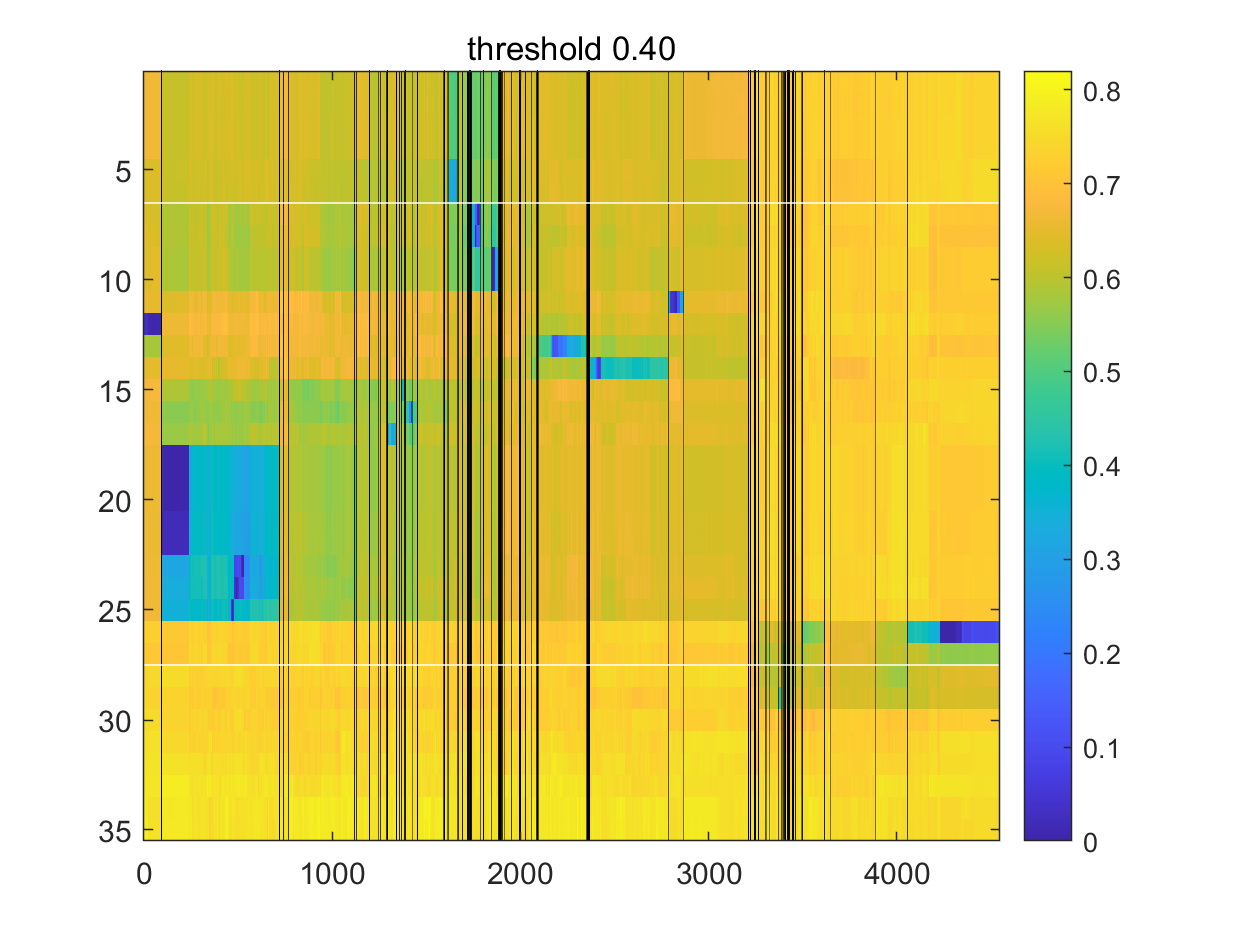

figure;
lw=0.05;
caxislim=[0,0.82];

labnum=1:119;
rec_candother=setdiff((1:(pickedrec.num-308))',[rec_candfpva;rec_candfpvb]);
a=ismember(changedleaforder_bygroups,labnum);
b=find(a==0);
changedleaforder_bygroups_1=changedleaforder_bygroups(b);
imagesc(refdistm_fpva(refreceptors.optleaforder,changedleaforder_bygroups_1));
hold on;
for g=1:totalgnum
    thisg_members=find(node_groupid(changedleaforder_bygroups_1)==g);
    groupsize(g)=length(thisg_members);
    plot((thisg_members(end)+1)*[1,1],[0,length(changedleaforder_bygroups_1)],'k','LineWidth',lw)
end

 plot([0,length(changedleaforder_bygroups_1)+1],(sum(refreceptors.typeid(refreceptors.tocheckseq(refreceptors.optleaforder))==2)+0.5)*[1,1],'w')
 plot([0,length(changedleaforder_bygroups_1)+1],(sum(refreceptors.typeid(refreceptors.tocheckseq(refreceptors.optleaforder))>0)+0.5)*[1,1],'w');
 %colorbar
caxis(caxislim)
xlim([0,length(changedleaforder_bygroups_1)+1])
title(sprintf('threshold %0.2f',test_distthresh))
colorbar


%%%%%%%%%%%%%%%%%%%%

## Figure 6c

Genomic distance (in base pairs) between Fpv-like receptors and its pyoverdine peptide synthetase gene (Pep) for annotated FpvA receptors (upper panel), FpvB receptors  (middle panel) and other receptors (lower panel). 

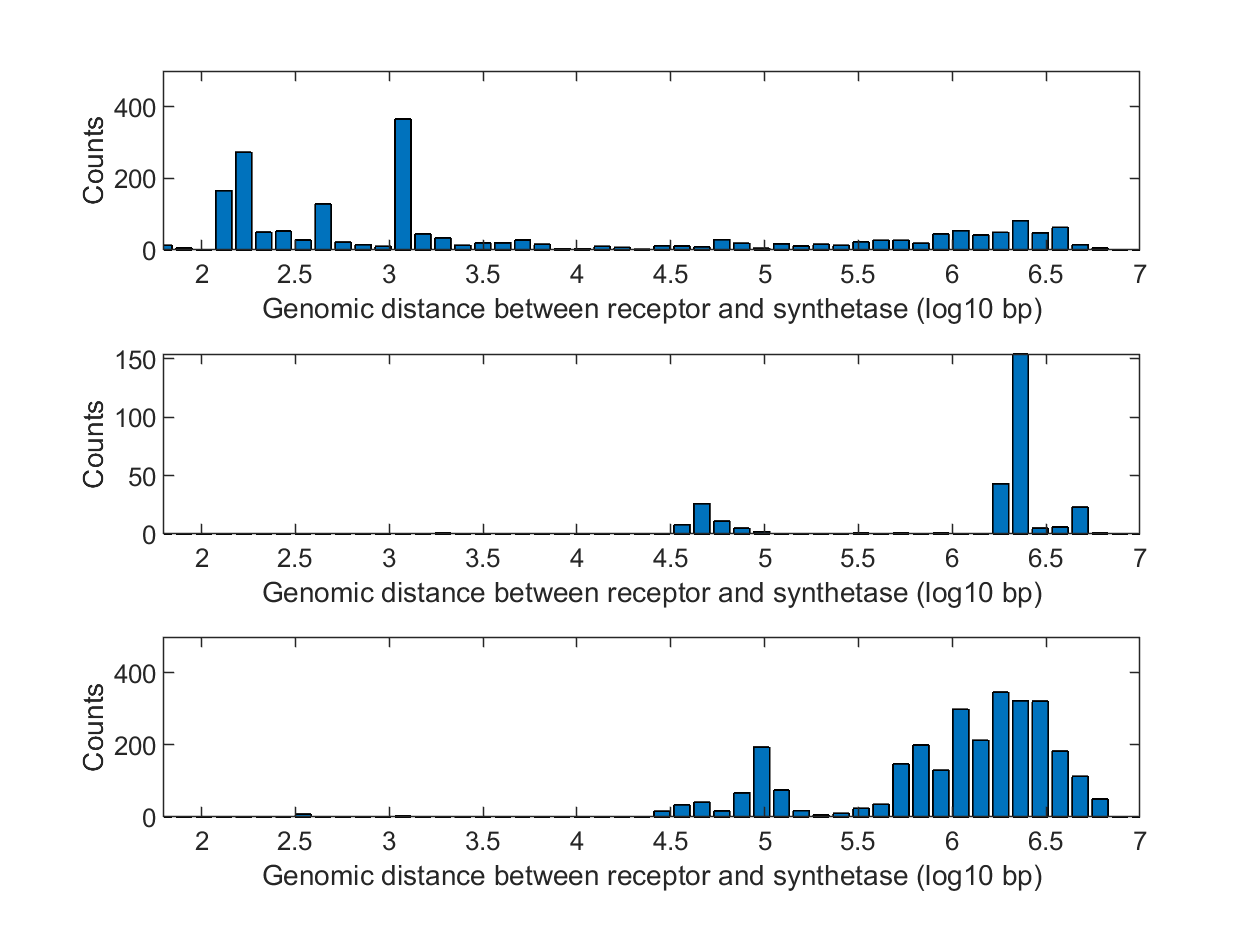

titlestr = 'others'

figure;
barnum=50;
for k=1:3
    subplot(3,1,k)
    if k==1
        cand=rec_candfpva;titlestr='fpvAs';
    elseif k==2
        cand=rec_candfpvb;titlestr='fpvBs';
    else
        cand=rec_candother;titlestr='others'
    end
    
    datatoshow=pickedrec_disttonrps(cand);
    
    datatoshow=log10(abs(pickedrec_disttonrps(cand)));boarders=[1.8,7];
    [bheight,barloc]=hist(datatoshow,linspace(boarders(1),boarders(2),barnum));
    bar(barloc,bheight);
    xlim([boarders(1),boarders(2)])
    xlabel('Genomic distance between receptor and synthetase (log10 bp)');
    if k~=2
        ylim([0,500])
    end    
    ylabel('Counts')
end

## Figure 6d

Distribution of the genomic distance between each fpvA receptor and its nearest pyoverdine peptide synthetase depending on whether the annotated fpvA receptor has high sequency similarity (blue, ≥ 50%) or low sequence similarity (yellow, < 50%) with at least one of the 21 reference FpvAs.

%remove lab strains from the data, that's for the "sequence-to-ecology"
%manuscript
if length(pickedrec_fpva.candself)>4547
    pickedrec_fpva_1=pickedrec_fpva;
    clear pickedrec_fpva;
end
pickedrec_fpva.speciesid=pickedrec_fpva_1.speciesid(120:end);
pickedrec_fpva.candself=pickedrec_fpva_1.candself(120:end);
pickedrec_fpva.fpvA_hmm_scorem=pickedrec_fpva_1.fpvA_hmm_scorem(120:end,:);
pickedrec_fpva.genekind=pickedrec_fpva_1.genekind(120:end);
pickedrec_fpva.locustag=pickedrec_fpva_1.locustag(120:end);
pickedrec_fpva.matchtoknown=pickedrec_fpva_1.matchtoknown(120:end);
pickedrec_fpva.mindist=pickedrec_fpva_1.mindist(120:end);
pickedrec_fpva.num=length(pickedrec_fpva.speciesid);
pickedrec_fpva.orderinpick=pickedrec_fpva_1.orderinpick(120:end);
pickedrec_fpva.rec_hmm_scorem=pickedrec_fpva_1.rec_hmm_scorem(120:end,:);
pickedrec_fpva.recs_dist_threetypes=pickedrec_fpva_1.recs_dist_threetypes(120:end,:);
pickedrec_fpva.recs_isminto_threetypes=pickedrec_fpva_1.recs_isminto_threetypes(120:end,:);
pickedrec_fpva.seqlen=pickedrec_fpva_1.seqlen(120:end);
pickedrec_fpva.seqs=pickedrec_fpva_1.seqs(120:end);
pickedrec_fpva.uninames=pickedrec_fpva_1.uninames(120:end);
%Find strains with the shortest genomic distance between receptor and synthesizetase in 1664 strains of bacteria
spname=[taxt.producer;taxt.partial_producer];
if size(mindist_toref,2)>4547
    mindist_toref_1=mindist_toref;
    clear mindist_toref;
    mindist_toref=mindist_toref_1(120:end);
end
mindist=struct();
for i=1:length(spname)
    name1=spname(i);
    a=find(ismember(pickedrec_fpva.uninames,name1));
    mindist(i).name=name1;
    temp=pickedrec_fpva.recs_dist_threetypes(a,2:3);
    temp_1=mindist_toref(a);
    temp=abs(temp);
    mindist(i).toPep=min( temp(:,1));
    mindist(i).toPeprecnum=find(temp(:,1)==min( temp(:,1)));
    mindist(i).Pepmindisttoref=temp_1(mindist(i).toPeprecnum);
   
    mindist(i).toTE=min( temp(:,2));
    mindist(i).toTErecnum=find(temp(:,2)==min( temp(:,2)));
   
    mindist(i).TEmindisttoref=temp_1(mindist(i).toTErecnum);
   
end
mindist_toPep=cell2table({mindist.toPep}');
mindist_toTE=cell2table({mindist.toTE}');
mindist_Pepmindisttoref=cell2table({mindist.Pepmindisttoref}');
mindist_TEmindisttoref=cell2table({mindist.TEmindisttoref}');
a=find(isnan(mindist_toPep.Var1));
b=find(~isnan(mindist_toPep.Var1));
c=find(isnan(mindist_toTE.Var1));
d=find(~isnan(mindist_toTE.Var1));

%only to TE
a1=intersect(d,a);
data1=mindist_toTE.Var1(a1);
data1_disttoref=cell2table(mindist_TEmindisttoref.Var1(a1));
%only to Pep
b1=intersect(b,c);
data2=mindist_toPep.Var1(b1);
data2_disttoref=cell2table(mindist_Pepmindisttoref.Var1(b1));
%to Pep and Te
c1=intersect(b,d);
data3_1=mindist_toTE.Var1(c1);
data3_2=mindist_toPep.Var1(c1);
data3_disttoref=cell2table(mindist_TEmindisttoref.Var1(c1));
a=find(data3_1<10000);
b=find(data3_2>10000);
c=intersect(a,b);
data_toTe=data3_1(c);
data1_1=[data1;data_toTe];
data1_1_disttoref=[data1_disttoref.Var1;data3_disttoref.Var1(c)];
a=1:115;
b=ismember(a',c);
c1=find(b==0);
data3_1_1=data3_1(c1);
data3_2_1=data3_2(c1);
data3_1_disttoref=data3_disttoref.Var1(c1);

data3=zeros(103,1);
for i=1:103
    if data3_1_1(i)>data3_2_1(i)
        data3(i,1)=data3_2_1(i);
    else
        data3(i,1)=data3_1_1(i); 
    end
end

data1_1(data1_1>20000)=25000;
data2(data2>20000)=25000;
data3(data3>20000)=25000;

mintoref_thresh=0.5;
FpvA=[data1_1;data2;data3];
data_disttoref=[data1_1_disttoref;data2_disttoref.Var1;data3_1_disttoref];
hasmindisttoref_1=(data_disttoref<mintoref_thresh);
hasmindisttoref_2=hasmindisttoref_1;

barnum=50;%50
for k=1:2
    if k==1
        cand=find(hasmindisttoref_2==1);titlestr='has ref';
        
        datatoshow=FpvA(cand);boarders=3*[0,1]*10^4;
        [bheight1,barloc1]=hist(datatoshow,linspace(boarders(1),boarders(2),barnum));
        
    elseif k==2
        cand=find(hasmindisttoref_2==0);titlestr='no ref';
   
        datatoshow=FpvA(cand);boarders=3*[0,1]*10^4;
    
        [bheight2,barloc2]=hist(datatoshow,linspace(boarders(1),boarders(2),barnum));
    end
end

data1_gsh=bheight1+bheight2;
data2_gsh=log10(data1_gsh+1);
data_gsh=[log10(bheight1+1);log10(bheight2+1)];
data_gsh=[((log10(bheight1+1) ./ (log10(bheight1+1)+log10(bheight2+1))).* data2_gsh);((log10(bheight2+1) ./ (log10(bheight1+1)+log10(bheight2+1))).* data2_gsh)]

data_gsh =     1.4842    1.1228    1.5108    1.1025    0.6792    0.7263    0.6373    1.0414    0.8736    0.5148    0.8372    0.4771       NaN    0.6990       NaN    0.2386    0.3010       NaN    0.3010       NaN         0         0         0    0.6021       NaN       NaN    0.3010       NaN    0.4771         0       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.6344       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.2693    1.2938    1.1687    0.8798    0.7010    0.4199    0.6637         0    0.4274    0.6313    0.2420         0       NaN         0       NaN    0.2386         0       NaN         0       NaN    0.4771    0.6990    0.3010         0       NaN       NaN         0       NaN         0    0.7782       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    0.7806       NaN       NaN       NaN       NaN       NaN       NaN       N

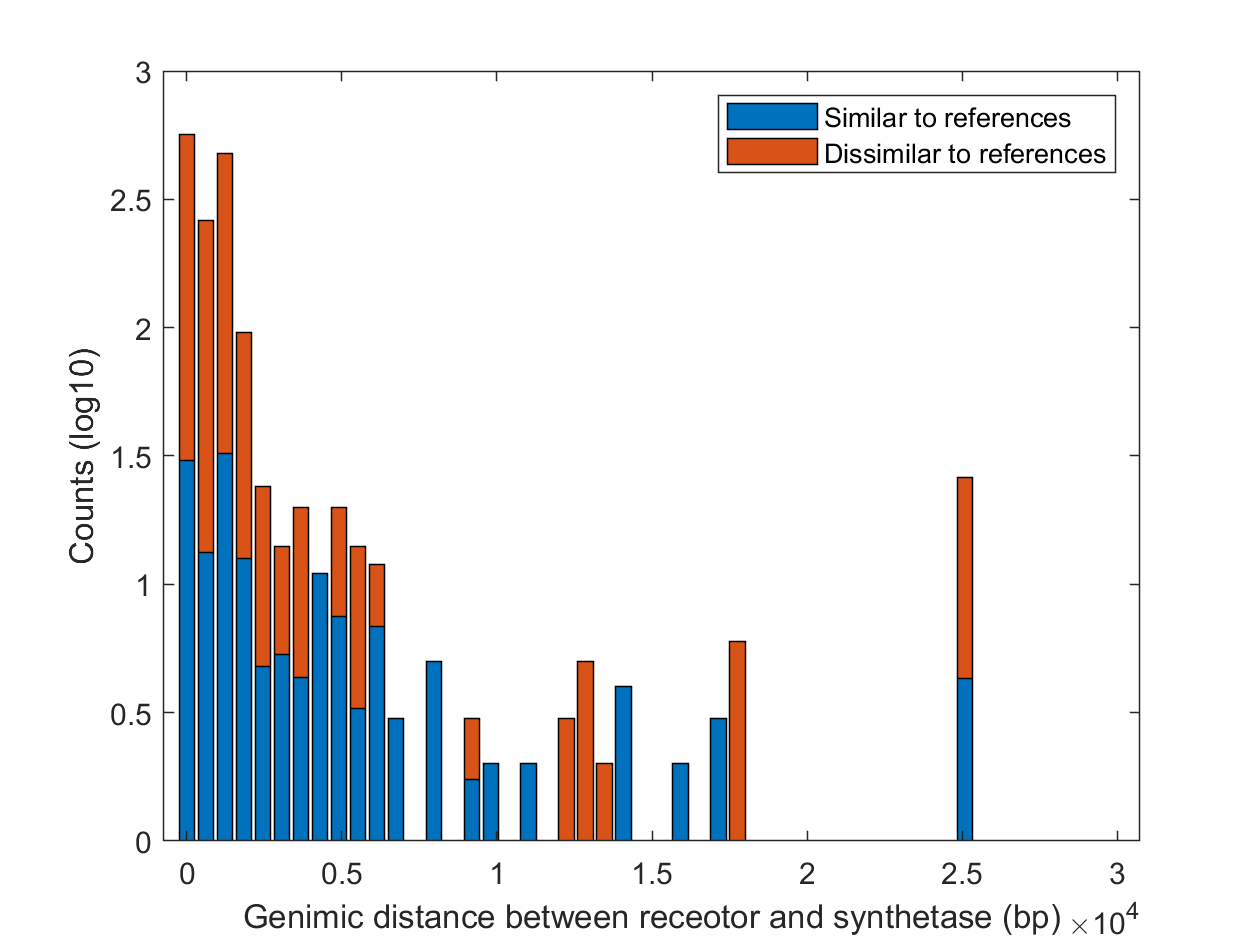

colors = [247/256 242/256 62/256; 0 255/256 255/256];
figure;
h=bar(barloc1,data_gsh',0.8,'stacked');
xlabel('Genimic distance between receotor and synthetase (bp)');
ylabel('Counts (log10)')
legend('Similar to references', 'Dissimilar to references', 'Location', 'northeast');

## Figure 6e

FpvA region-based conservation scores from a multi-alignment of all the annotated FpvA receptors that are proximate (< 20 kbp) to the pyoverdine synthetase cluster mapped to the FpvA sequence of strain P. aeruginosa PAO1. 


thresgenomedist=2*10^4;
reces_has_distototype3=find(~isnan(pickedrec_fpva.recs_dist_threetypes(:,3)) );
reces_has_distototype2=find(~isnan(pickedrec_fpva.recs_dist_threetypes(:,2)) );
reces_has_distototype2_3=union(reces_has_distototype2,reces_has_distototype3);
recs_candself_3=find(abs(pickedrec_fpva.recs_dist_threetypes(:,3))<thresgenomedist);
recs_candself_3=intersect(recs_candself_3,reces_has_distototype3);
recs_candself_2=find(abs(pickedrec_fpva.recs_dist_threetypes(:,2))<thresgenomedist);
recs_candself_2=intersect(recs_candself_2,reces_has_distototype2);
recs_candself=union(recs_candself_2,recs_candself_3);
for i=1:length(recs_candself)
    rid=recs_candself(i);
    pickedrec_fpva.proxirec(rid,1)=1;
end
if length(pickedrec_fpva.proxirec)<4547
    pickedrec_fpva.proxirec(end+1)=0;
end
[~,fastaseq]=fastaread('./data/fpva_4666_aligned.fasta');
%delete lab strains
 fpvas_aligned_6047='';
 num=0;
 for i=120:length(fastaseq)
     num=num+1;
     fpvas_aligned_6047(num,:)=fastaseq{i};
 end

if size(refdistm_fpva,2)>4547
    refdistm_fpva_1=refdistm_fpva;
    clear refdistm_fpva;
end
refdistm_fpva=refdistm_fpva_1(:,120:end);
surerec=find(pickedrec_fpva.proxirec==1);
pao1rec=find(refdistm_fpva(1,:)<0.0013,1);

surerec=[pao1rec;surerec];
surerecseq_align=fpvas_aligned_6047(surerec,:);
pao1rec_locinsurerecseq_align=1;

%surerec cluster
test_distthresh=0.4;
load ./data/seqdist4666.mat;
if size(seqdist4666,1)>4547
    seqdist4666_1=seqdist4666;
    clear seqdist4666;
end
seqdist4666=seqdist4666_1(120:end,120:end);
caxislim=[0,0.82];
seqdist1231=seqdist4666(surerec,surerec);
% try to mark groups
fpvaseqdist=linkage(seqdist1231,'single');
optleaforderfpva = optimalleaforder(fpvaseqdist,seqdist1231);
[node_groupid,totalgnum,changedleaforder_bygroups] = Cluster_byconnection(seqdist1231,test_distthresh,optleaforderfpva);
totalgnum

totalgnum = 44

suregroup=unique(node_groupid);
length(suregroup)

ans = 44

pao1loc=pao1rec_locinsurerecseq_align;
sele_mualign=surerecseq_align;
[sele_CSeq, sele_Score] = seqconsensus(sele_mualign);
gapfreq=sum(sele_mualign=='-')/size(sele_mualign,1);
conservescore=(max(sele_Score)-sele_Score).*(1-gapfreq);
existinPao1=find(sele_mualign(pao1rec_locinsurerecseq_align,:)~='-' & sele_mualign(pao1rec_locinsurerecseq_align,:)~='*');
mullocinpao1=cumsum(sele_mualign(pao1rec_locinsurerecseq_align,:)~='-'& sele_mualign(pao1rec_locinsurerecseq_align,:)~='*');
freq=tabulate(node_groupid);
H=Entropy(freq(:,2))

H = 3.6147

% the reduced entropy along the group
mul_int=aa2int(sele_mualign);
mulinfor_group=zeros(1,size(sele_mualign,2));
for i=1:size(sele_mualign,2)
    [H1,H2,CH1_given2,CH2_given1,mulin]=ZL_Mulinfor_int(mul_int(:,i),node_groupid);
    mulinfor_group(i)=mulin/H2;
end
threshhold_conservescore=0.95;
templist=find(conservescore>threshhold_conservescore*max(conservescore));
% where are the three domains
seperateposi=templist(1);
for i=2:(length(templist)-1)
    if templist(i)-templist(i-1)>15
        seperateposi(end+1)=templist(i);
    end
end
seperateposi=unique([1,seperateposi,length(conservescore)]);
sep_se=[seperateposi(1:(end-1))',seperateposi(2:end)'-1];
sep_se(end,2)=length(sele_Score);
clustering_score=zeros(1,size(sep_se,1));
unigs=unique(node_groupid); 
clustering_twoscore=[];
for i=1:size(sep_se,1)
    sp=sep_se(i,1);
    ep=sep_se(i,2);
    scorem=squareform(seqpdist(sele_mualign(:,sp:ep),'Method','p-distance'));
    arrange=[];
    dist_between=zeros(length(unigs));
    std_within=zeros(1,length(unigs));
    for g1=1:length(unigs)
        members_1=find(node_groupid==unigs(g1));
        arrange=[arrange,members_1];
        for g2=g1:length(unigs)
            members_2=find(node_groupid==unigs(g2));
            tempdistm=scorem(members_1,members_2);
            if g1==g2 
                if length(tempdistm)>1
                    dataline=squareform(tempdistm);
                    std_within(g1)=mean(dataline);
                else
                    std_within(g1)=nan;
                end
            else
                dataline=tempdistm(:);
            end
            dist_between(g1,g2)=mean(dataline);
            dist_between(g2,g1)=dist_between(g1,g2);
        end
    end
    weighted_between=dist_between;
    
    for k=1:size(weighted_between,1)
        weighted_between(k,k)=nan;
    end
    
    clustering_twoscore(i,:)=[mean(weighted_between(:),'omitnan'),mean(std_within,'omitnan')]; 
    clustering_score(i)=mean(weighted_between(:),'omitnan')/mean(std_within,'omitnan');   
end

figure;
colortable=colormap(jet);
subplotnum=10;
subplot(subplotnum,1,1:(subplotnum-1))

hold on;
xlist=1:length(existinPao1);
plot(xlist,conservescore(existinPao1),'k');
scatter(mullocinpao1(seperateposi),conservescore(seperateposi),30,'k','filled')

mincolorv=min(clustering_score)%3;

mincolorv = 3.8785

maxcolorv=max(clustering_score)%15;

maxcolorv = 11.8935

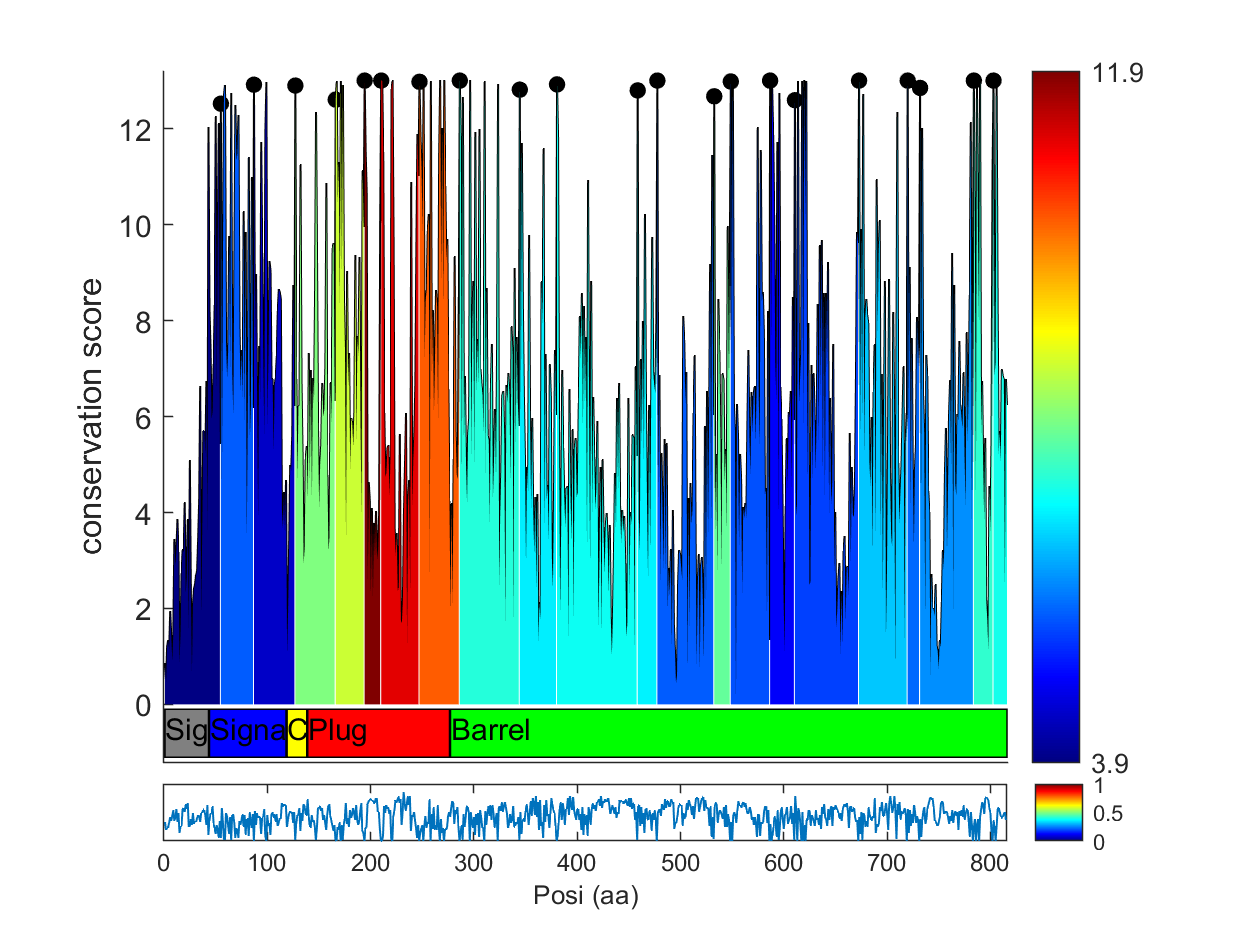


for i=1:size(sep_se,1)
    sp=sep_se(i,1);
    ep=sep_se(i,2);
    splist=intersect(sp:ep,existinPao1);
   
    % how many can be traced into the first 21
    cscore=clustering_score(i);
    colorid=min(size(colortable,1),max(1,round(size(colortable,1)*(cscore-mincolorv)/(maxcolorv-mincolorv))));

    fh=fill(mullocinpao1([splist(1),splist,splist(end)]),[0,conservescore(splist),0],colortable(colorid,:));
    
    fh.LineStyle='none';
    
end


% mark the poisition for domains
refreceptors.pao1_ses=[1,43;
    44,118;
    119,138;
    139,276;
    277,815];
refreceptors.annostr={'Signaling Sequence';
    'Signaling';
    'Connecting loop';
    'Plug';
    'Barrel'};

refreceptors.color=[0.5,0.5,0.5;
    0,0,1;
    1,1,0;
    1,0,0;
    0,1,0];


height=1;
for i=1:size(refreceptors.pao1_ses)
    startp=refreceptors.pao1_ses(i,1);
    stopp=refreceptors.pao1_ses(i,2);
    colorcode=refreceptors.color(i,:);
    annostr=refreceptors.annostr{i};
    
    patch([startp,stopp,stopp,startp],-0.1+[-1,-1,0,0]*height,colorcode);
    text(startp,-0.5,annostr)
end
ch=colorbar;
ch.Ticks=[0,1];
ch.TickLabels= strsplit(sprintf('%0.1f ',[mincolorv,maxcolorv]));
xlim([0,length(existinPao1)+1])
ylim([-1.2,max(conservescore)+0.2])
xticks([])
ylabel('conservation score');


subplot(subplotnum,1,subplotnum)
xlist=1:length(existinPao1);
plot(xlist,mulinfor_group(existinPao1))
xlim([0,length(existinPao1)+1])
yticks([])
xlabel('Posi (aa)')
colorbar

## Figure 6f

Hierarchically clustered distances between the 4547  FpvA receptors based on their feature sequences (comprising the four groups with the highest identification scores). 94 receptor groups are identified by 70% identity threshold

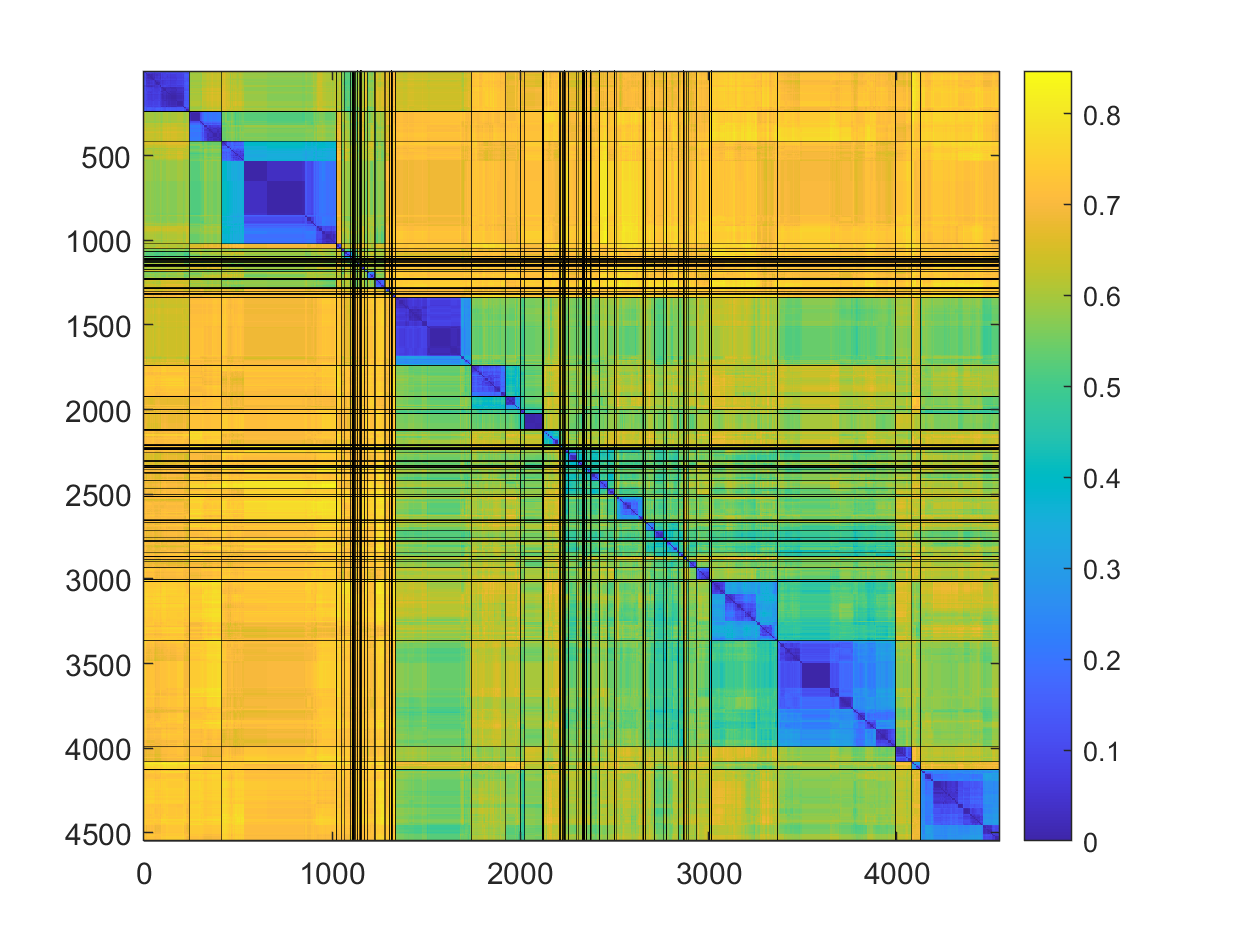

distm_rec=rec.seqdist678910;
figure;
lw=0.05;
pnum=20;
imagesc(distm_rec(leaforder_alonesp_new,leaforder_alonesp_new));
hold on;

rec.straintype(1:986,1)=1;
cheater1name=find(strcmp(rec.strainnames,taxt.cheater(1)));
rec.straintype(987:(cheater1name(1)-1),1)=2;
rec.straintype(cheater1name(1):rec.datanum,1)=3;

groupsize=zeros(1,totalgnum_new);
group_typebelong=zeros(3,totalgnum_new);
group_selfnum=zeros(1,totalgnum_new);
for g=1:totalgnum_new
    members_rec=find(recgroup_new==g);
    
    members_straintype=rec.straintype(members_rec);
    group_typebelong(:,g)=[sum(members_straintype==1),sum(members_straintype==2),sum(members_straintype==3)];
    
    group_selfnum(g)=sum(rec.candyself(members_rec));
    
    thisg_members=find(recgroup_new(leaforder_alonesp_new)==g);
    groupsize(g)=length(thisg_members);
    plot([0,length(leaforder_alonesp_new)],(thisg_members(end)+1)*[1,1],'k','LineWidth',lw);
    plot((thisg_members(end)+1)*[1,1],[0,length(leaforder_alonesp_new)],'k','LineWidth',lw);
end


groupassigncolor=find(group_typebelong(1,:)>0);
[~,order]=sort(group_typebelong(1,groupassigncolor));
miny=-200;
barheight=195;

hold on;
for g=1:totalgnum_new
    bw=2;
    members_rec=find(recgroup_new==g);
    locinassign=find(groupassigncolor==g);
    if ~isempty(locinassign)
       
        
         members_rec=find(recgroup_new==g);
         members_straintype=rec.straintype(members_rec);
         members_rec_pure=members_rec(members_straintype==1);
         
         locsinorder=sort(find(ismember(leaforder_alonesp_new,members_rec_pure)));
         setables=[];
         s=locsinorder(1);
         for j=1:length(locsinorder)
             
             if j==length(locsinorder)||(j>1 && ((locsinorder(j)-locsinorder(j-1))>1))'
                 if j>1
                     e=locsinorder(j-1);
                 else
                     e=s;
                 end
                 setables(end+1,:)=[s-0.5,e+0.5];
                 s=locsinorder(j);
                 
             end
            
         end
    end
end
colorbar
xlim([0,length(leaforder_alonesp_new)+1]);

## Figure 6g

The diversity of FpvA receptors along the 13 phylogeny clades containing more than 1 strain.

"phygroup_0308_syndist.xlsx" contains the phylogenetic distance between strains

"pyoverdine_digital_1664.xlsx" contains the product predictions of all strains

phygroup_syz=readtable('./data/phygroup_0308_syndist.xlsx');

phygroup=phygroup_syz.phygroup0_3_18_;
aaa=tabulate(phygroup);
phygroup_above2=find(aaa(:,2)>1);
digital=readtable('./data/pyoverdine_digital_1664.xlsx');
for i=1:length(phygroup_syz.Species)
    a=ismember(rec.strainnames,phygroup_syz.Species{i});
    recgroup_temp=recgroup_new(a);
    sp1928(i).spanme=phygroup_syz.Species{i};
    sp1928(i).phyg=phygroup(i);
    sp1928(i).recg=sort(recgroup_temp); 
    sp1928(i).len=length(recgroup_temp);
   
end
max([sp1928.len])

ans = 21

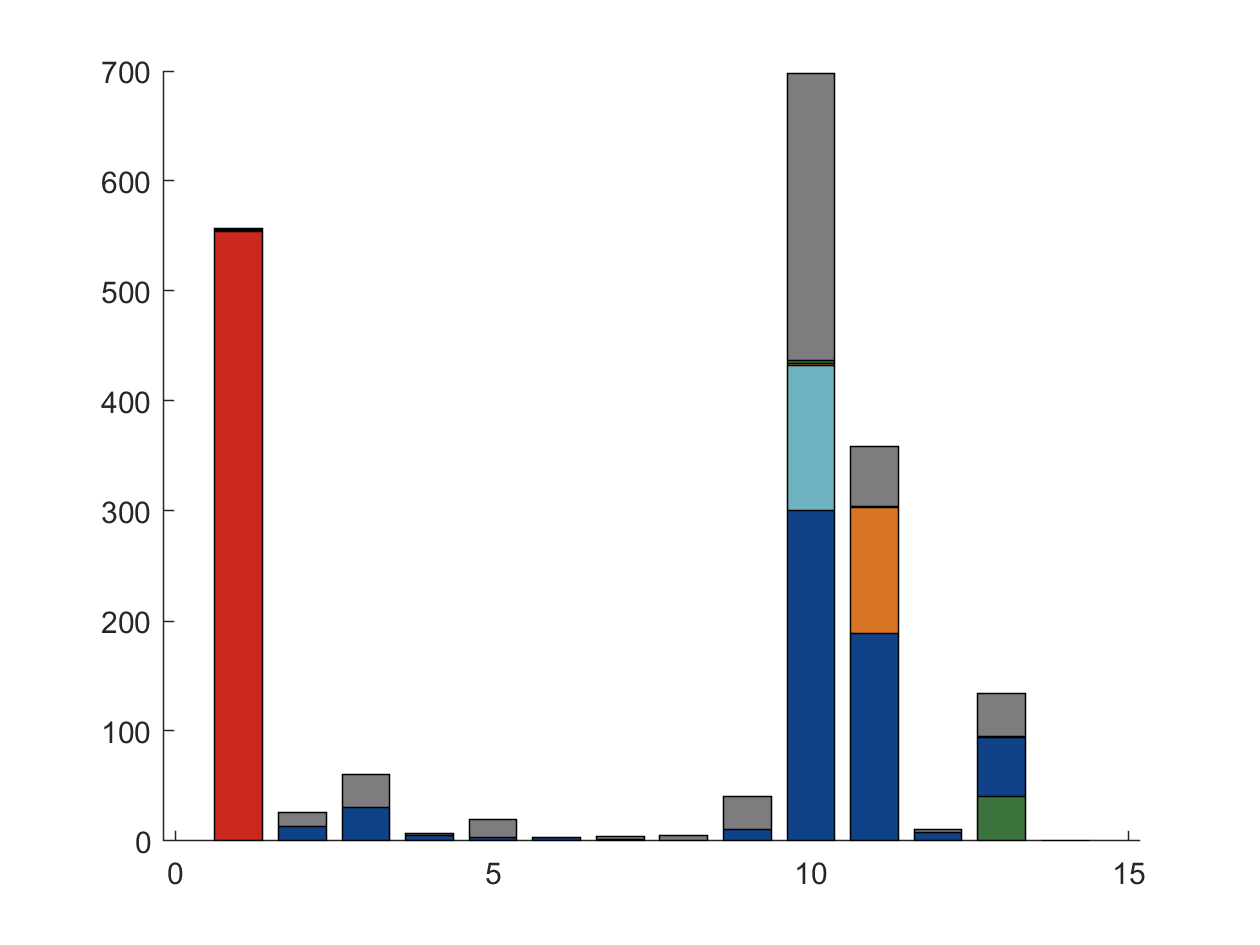

clear recnumchar;
recnum=zeros(1928,21);
for i=1:1928
    temp=sp1928(i).recg;
    
    for j=1:length(temp)
        recnum(i,j)=temp(j);
    end
end


for i=1:length(recnum)
    tem_char = '';
    for j=1:21
        
        tem_char = [tem_char,'-',num2str(recnum(i,j))];
           
    end
    tem_char(1) = [];
    sp1928(i).reccomb=tem_char;
end

H_score=100*ones(length(aaa),3);
H_score(:,1)=1:length(aaa);
for i=1:length(phygroup_above2)
    phyg=phygroup_above2(i);
    a=find(phygroup==phyg);
    %rec combination
    temp_reccomb_phyg1={sp1928.reccomb};
    temp_reccomb_phyg2=temp_reccomb_phyg1(a);
    b_phyg2=tabulate(temp_reccomb_phyg2);
    p_phy=cell2table(b_phyg2(:,3));
    H_phy1=-log2(p_phy.Var1/100);
    H_phy2=(p_phy.Var1/100) .* H_phy1;
    H_reccomb=sum(H_phy2);
    %rec group
    temp_rec_phyg1=[sp1928(a).recg];
    b_recg=tabulate(temp_rec_phyg1);
    b_temp=find(b_recg(:,2)>0);
    b_recg2=b_recg(b_temp,:);
    p_recg2=b_recg2(:,3)/100;
    H_recg1=-log2(p_recg2);
    H_recg2= p_recg2 .* H_recg1;
    H_recg=sum( H_recg2);
    H_score(phyg,2)=H_reccomb;
    H_score(phyg,3)=H_recg; 
end

for i=1:1928
    g1=sp1928(i).phyg;
    sp1928(i).Hreccomb=H_score(g1,2);
    sp1928(i).Hrecg=H_score(g1,3);        
end
xx1={sp1928.Hrecg}';
xx2=cell2mat(xx1);
a=find(xx2==100);
for i=1:length(a)
    sp1928(a(i)).Hrecg=nan;
end
data=readtable('./data/Rec_div_0309.xlsx');
domainsp=["aeruginosa","fluorescens","syringae","putida","sp"];
usedata=struct();
num=0;
for i=1:length(aaa)
    a=find(data.phygroup==i);
    if length(a)>1
        
        temp=data.species(a);
        b=tabulate(temp);
        c=find(ismember(b(:,1),domainsp));
        d=find(~ismember(b(:,1),domainsp));
        for j=1:length(c)
            num=num+1;
            usedata(num).phygroup=i;
            usedata(num).spname=b(c(j),1);
            temp1=cell2table(b(c(j),2));
            usedata(num).num=temp1.Var1;
        end  
        num=num+1;
        usedata(num).phygroup=i;
        usedata(num).spname='Other';
        f=cell2table(b(d,2));
        usedata(num).num=sum(f.Var1);
    end
end
color6=[202/255,39/255,30/255;110/255,179/255,191/255;216/255,117/255,36/255;61/255,115/255,60/255;16/255,66/255,135/255;125/255,125/255,128/255];
color_matrix=zeros(length(usedata),3);
for i=1:length(usedata)
    if strcmp(usedata(i).spname,"aeruginosa")
       color_matrix(i,:)=color6(1,:);
    elseif strcmp(usedata(i).spname,"fluorescens")
       color_matrix(i,:)=color6(2,:);
    elseif strcmp(usedata(i).spname,"syringae")
       color_matrix(i,:)=color6(3,:); 
    elseif strcmp(usedata(i).spname,"putida")
       color_matrix(i,:)=color6(4,:); 
    elseif strcmp(usedata(i).spname,"sp")
       color_matrix(i,:)=color6(5,:); 
    elseif strcmp(usedata(i).spname,"Other")
       color_matrix(i,:)=color6(6,:); 
    end
end
value_phyg=readtable('./data/value_phygroup_0309.xlsx');
value_1=table2array(value_phyg);
X=value_1(:,2:6);
num=0;
figure
hold on
for i=1:13 
    if i>1
        a=find(~isnan(X(i,:)));
        c=find(~isnan(X((i-1),:)));
        b=bar(i:i+1,[X(i,1:length(a));zeros(1,length(a))],0.75,'stacked');
        num=num+length(c);
        for j=1:length(a)
            set(b(j),'facecolor',color_matrix(num+j,:))
        end
    else
        a=find(~isnan(X(i,:)));
        b=bar(i:i+1,[X(i,1:length(a));zeros(1,length(a))],0.75,'stacked');
        for j=1:length(a)
            set(b(j),'facecolor',color_matrix(j,:))
        end 
    end
    
end

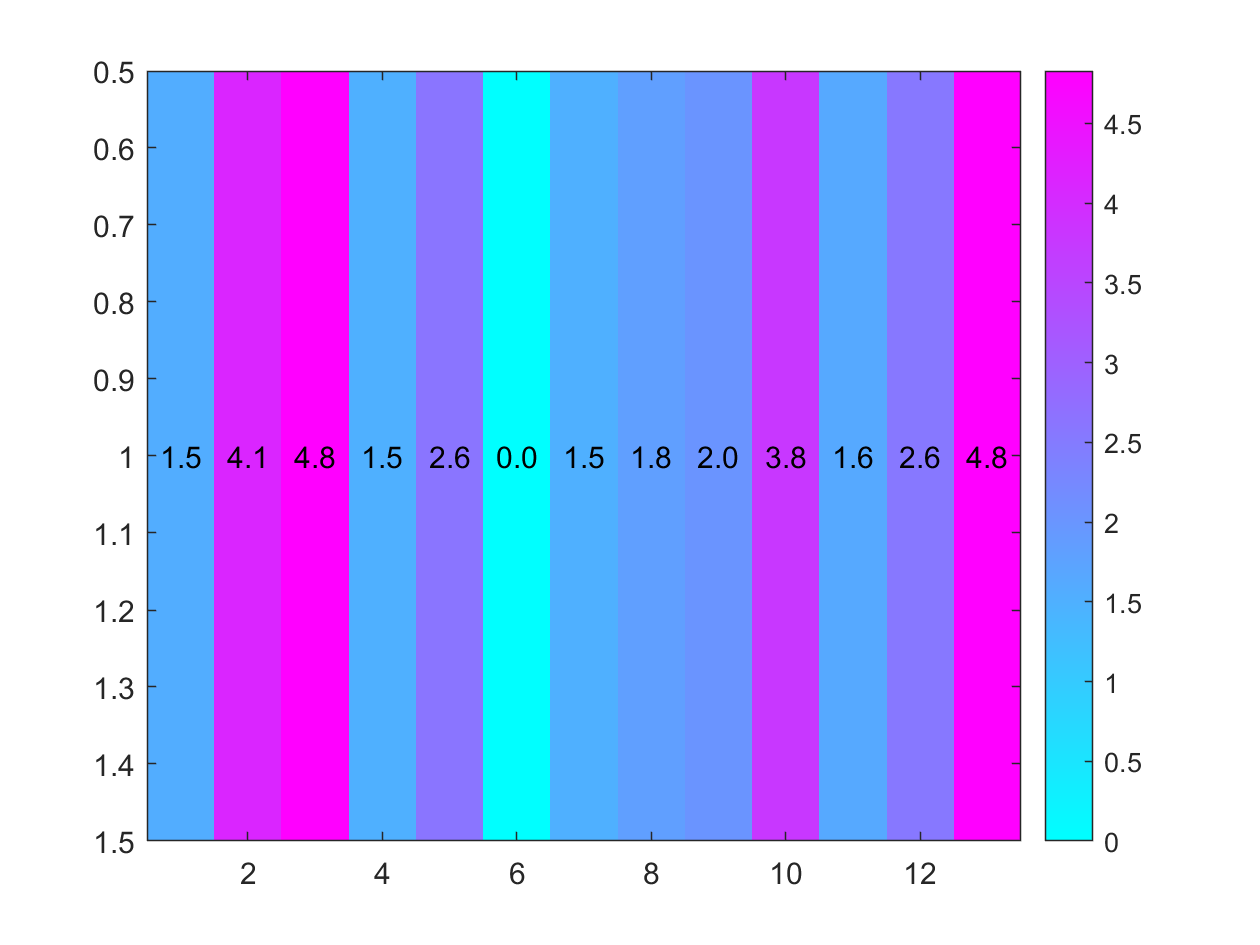



H_recg_use=zeros(13,1);
usephygroup=value_1(:,1);
for i=1:size(usephygroup,1)
    g1=usephygroup(i);
    a=find(data.phygroup==g1);
    H_recg_temp=data.H_recg(a);
    H_recg_use(i,1)=H_recg_temp(1);
end

figure,
data_recdiv=H_recg_use';
imagesc(data_recdiv);
colormap("cool");
colorbar
hold on;
for s=1:length(H_recg_use)
    for r=1
        xloc=s;
        yloc=r;
        
        text(xloc,yloc,sprintf('%.1f',data_recdiv(r,s)),'HorizontalAlignment', 'center')
    end
end

## Figure S4

Comparison of clustering and grouping effects of complete sequences (a) and feature sequences (b) of all proximate-receptors

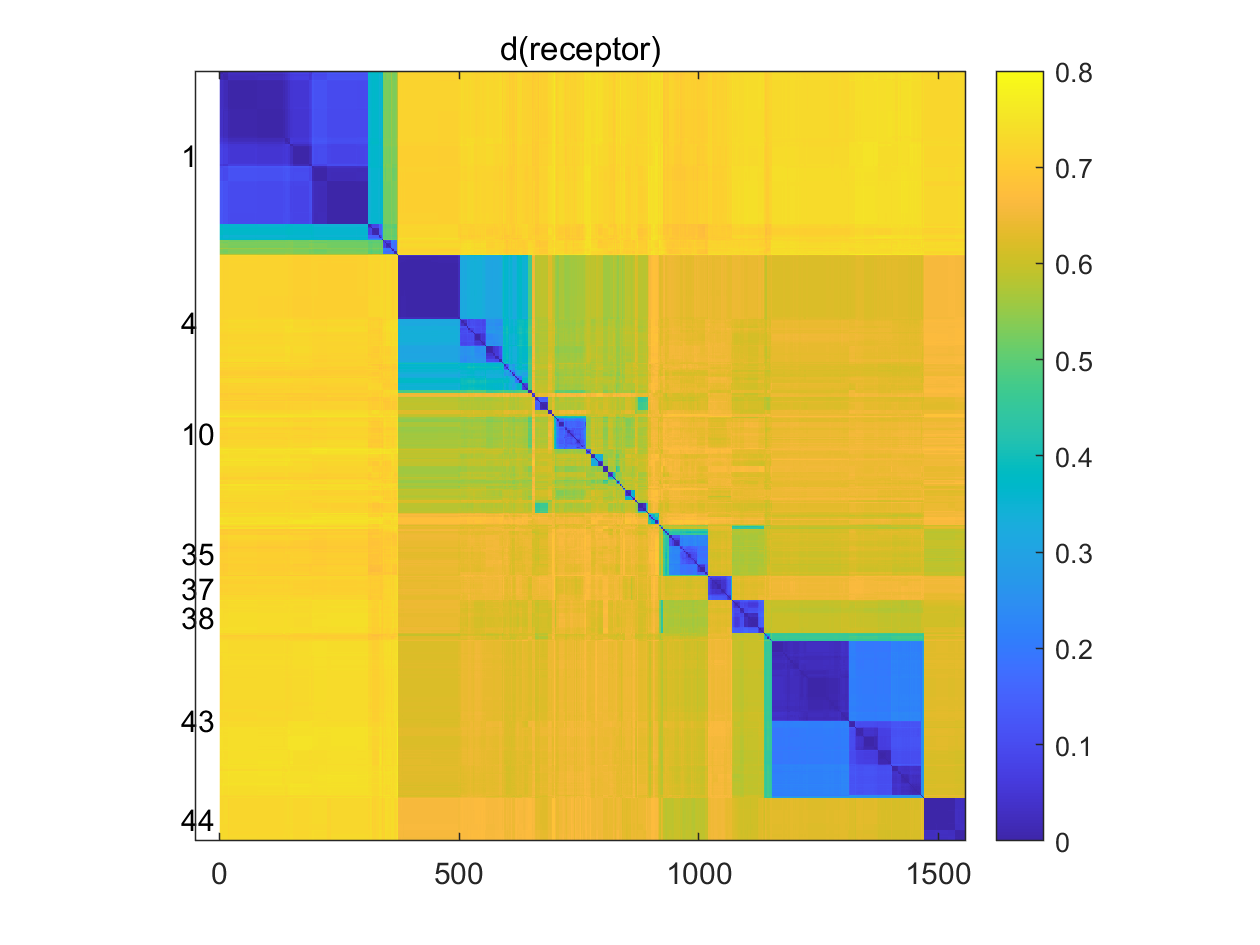

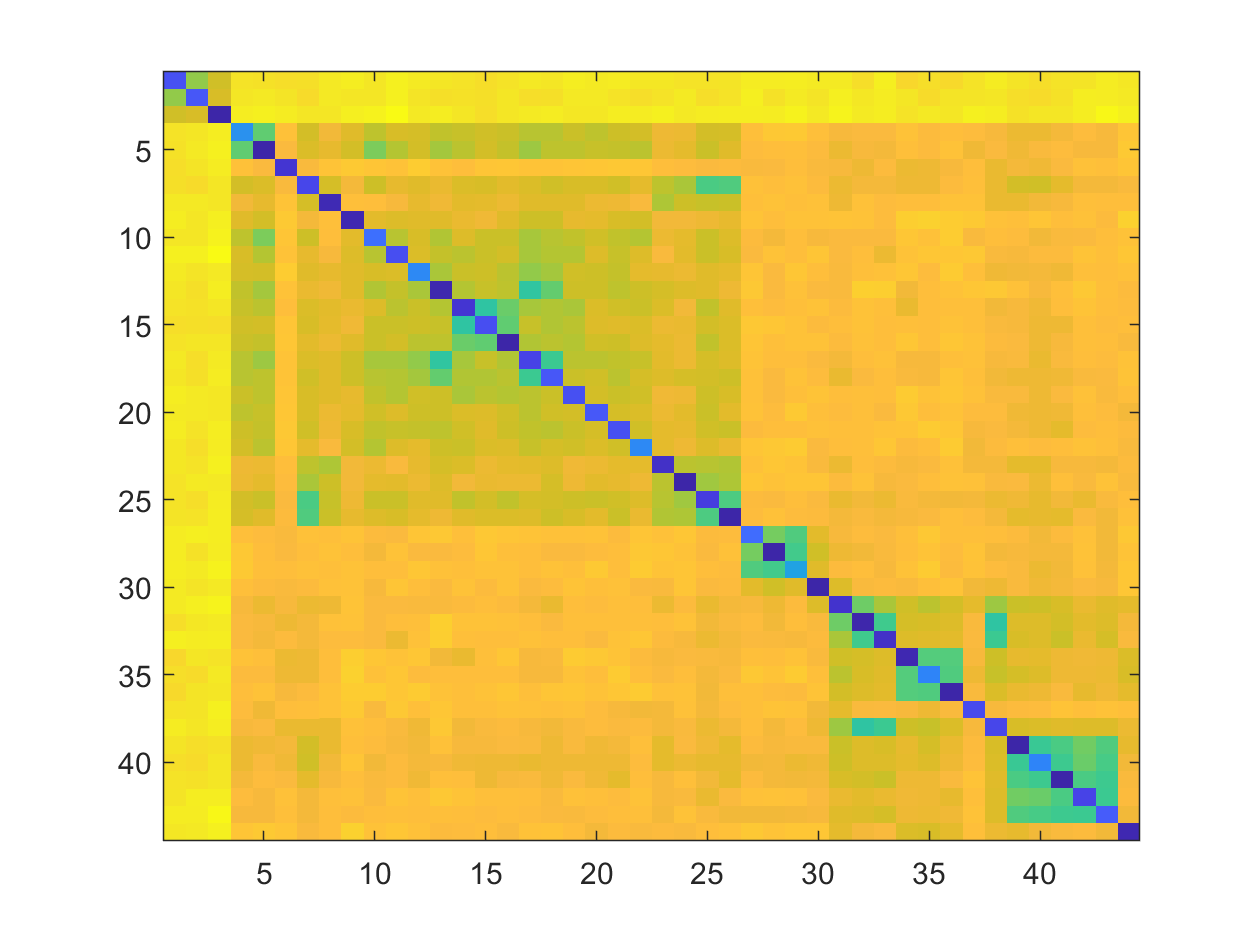

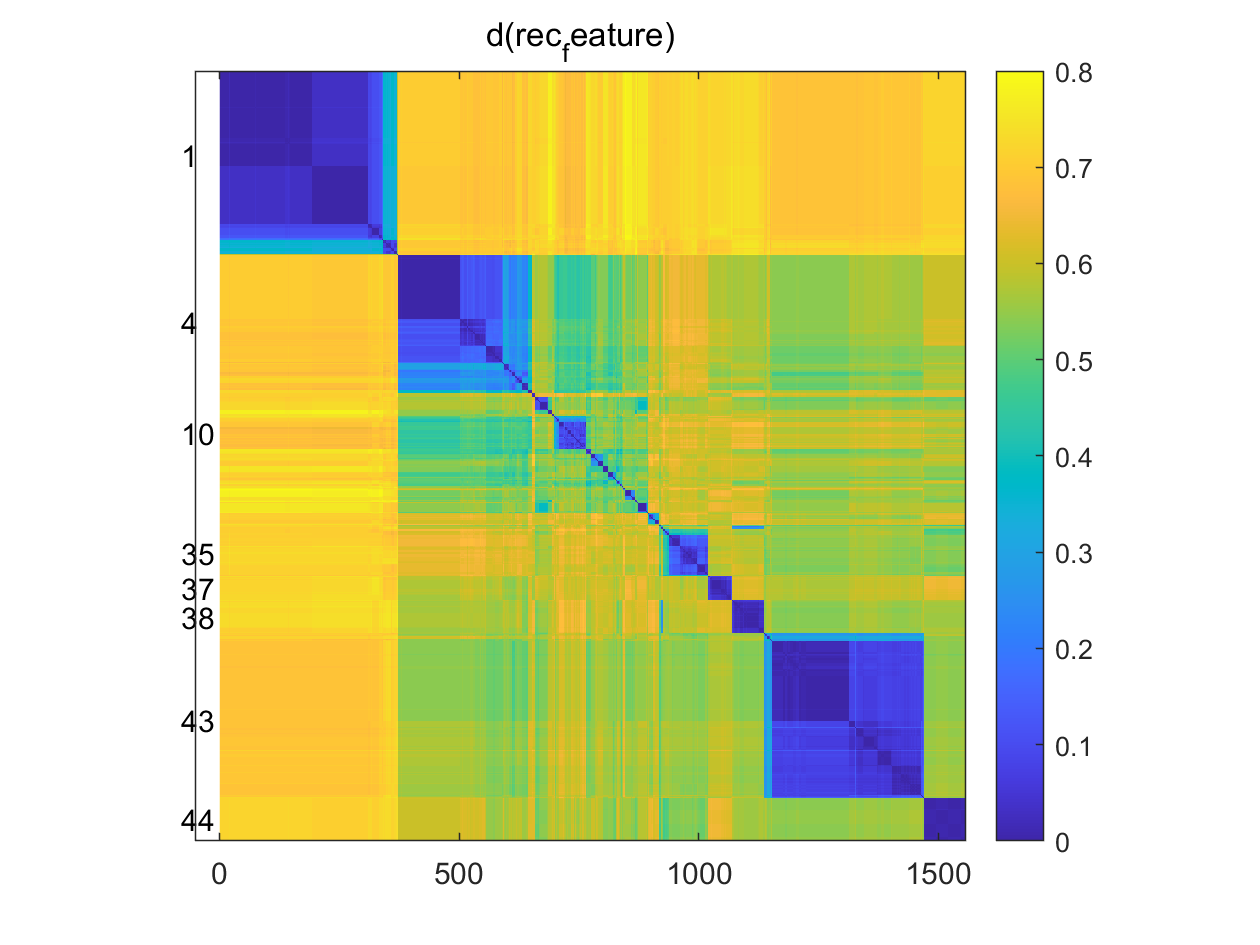

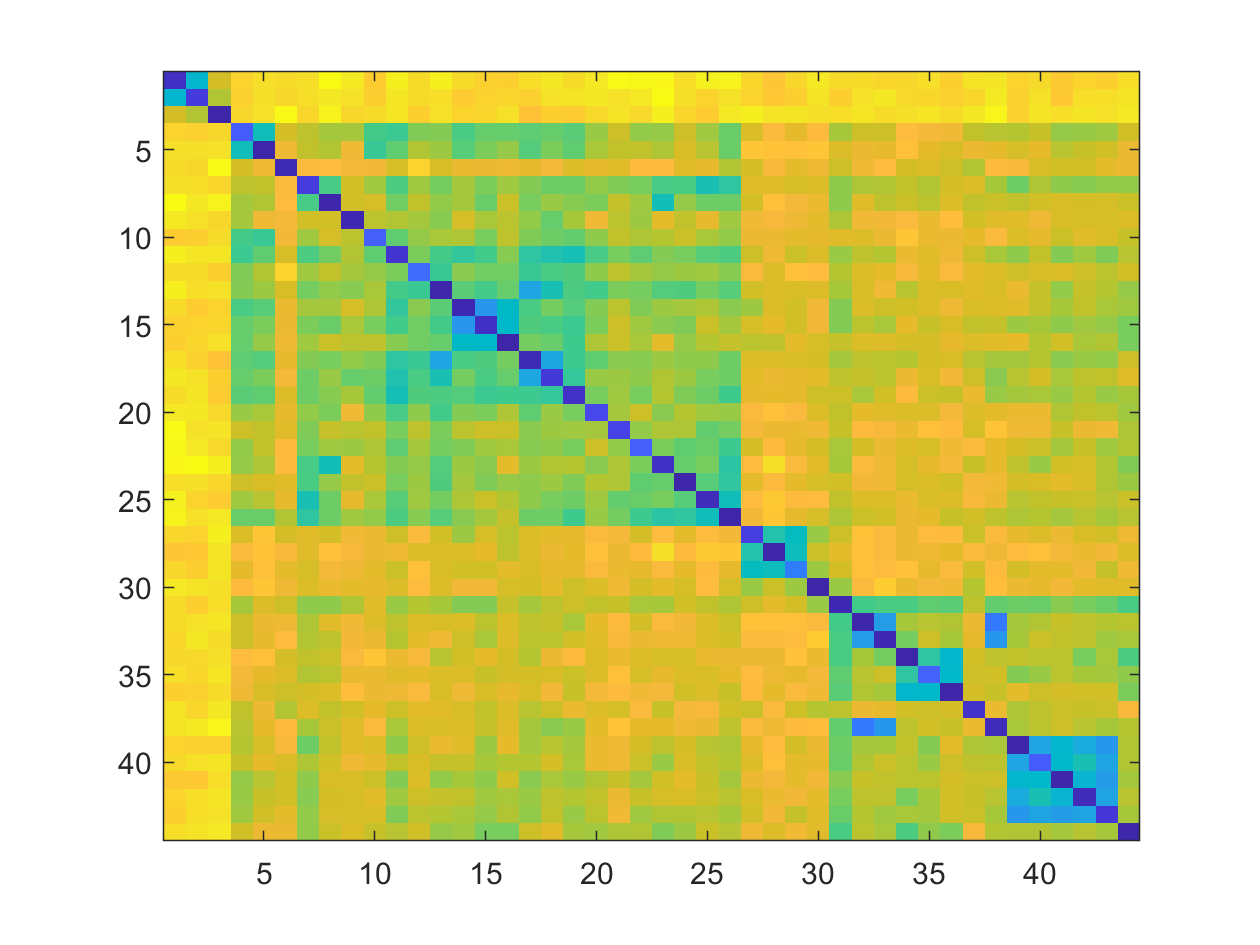

leaforder_alonesp=changedleaforder_bygroups;
distm_rec=seqdist1231;
recgroup=node_groupid;
groupfreq=tabulate(recgroup);
rec_groupsize=groupfreq(:,2);
[~,recgroup_orderbysize]=sort(rec_groupsize,'descend');
figure;
groupsize_thresh=31;
linecolor=0*[0.8,0,0.8];
linewidth=1.2;
for k=1:2%:3
    figure;
    if k==1
    toplotm=seqdist1231(leaforder_alonesp,leaforder_alonesp);
    titlestr='d(receptor)';
    elseif k==2
    scorem=squareform(seqpdist(sele_mualign(:,sep_se(5,1):sep_se(8,2)),'Method','p-distance'));
    toplotm=scorem(leaforder_alonesp,leaforder_alonesp);
     titlestr='d(rec_feature)';
    end
    imagesc(toplotm);
    hold on;
    average_m=zeros(totalgnum);
    for g=1:totalgnum
       
        thisg_members=find(recgroup(leaforder_alonesp)==g);
        for r=1:g
            rg_member=find(recgroup(leaforder_alonesp)==r);
            tempm=toplotm((thisg_members),(rg_member));
            average_m(g,r)=mean(tempm(:));
            average_m(r,g)=average_m(g,r);
        end
        if length(thisg_members)>groupsize_thresh
            text(-80, mean(thisg_members),num2str(g));
        end
    
    
      
        ph.LineStyle='none';
    
    end
    
    set(gca,'ytick',[])
    xlim([-50,length(leaforder_alonesp)+1])
    
    title(titlestr)
    colorbar
    caxis([0 0.8])
    axis square
    
    xx=distm_rec(leaforder_alonesp,leaforder_alonesp);
    x=xx(:);
    y=toplotm(:);
    tokeep=(~isnan(x) & ~isnan(y));
    corm=corrcoef(x(tokeep),y(tokeep));
    
    figure;
    imagesc(average_m)
end

## Figure S5

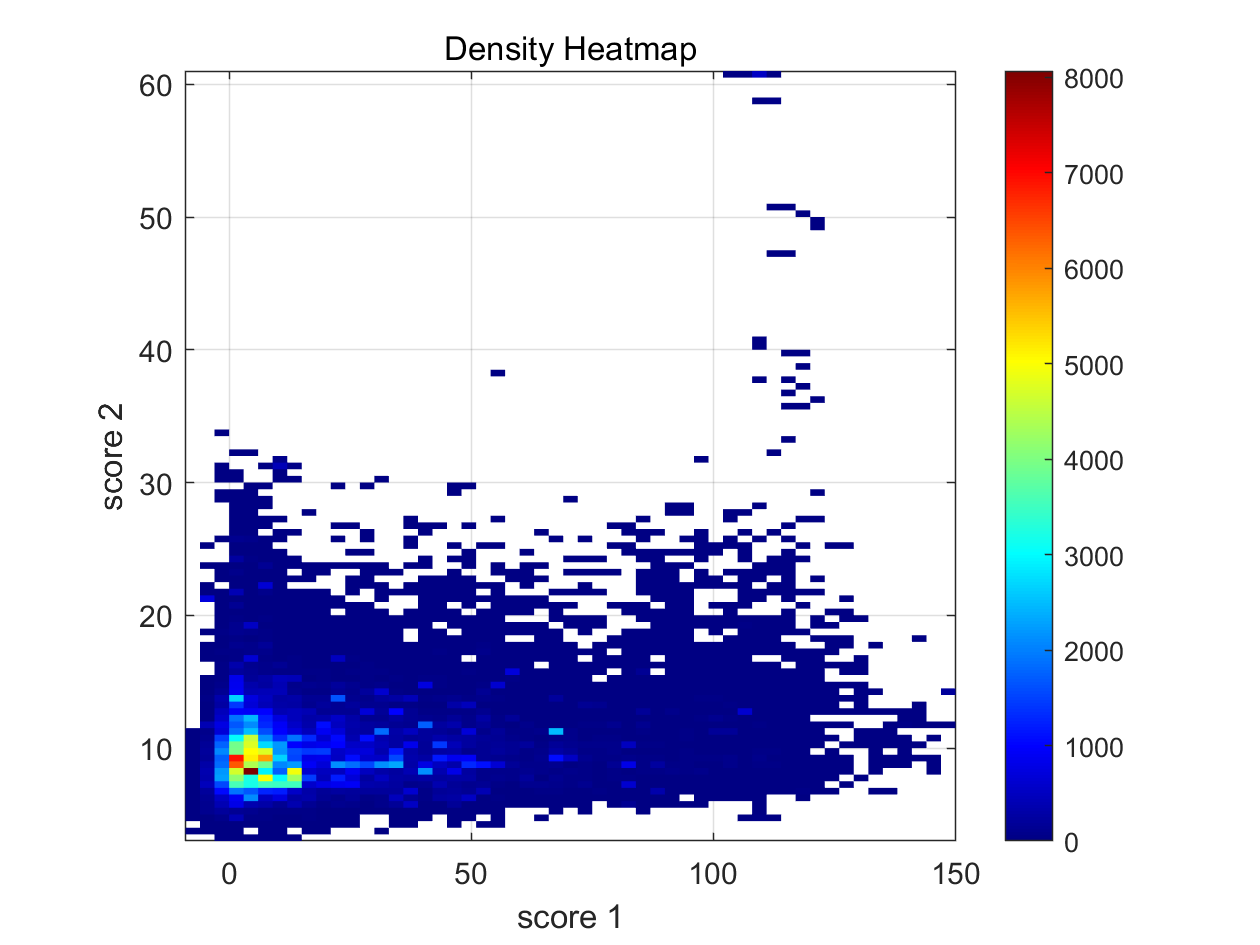

x = fpvA_hmm_scorem(:,1);
y = fpvA_hmm_scorem(:,2);
pickthresh=[50,30];

figure;
heatmap = histogram2(x, y, 'DisplayStyle', 'tile', 'ShowEmptyBins', 'off');
heatmap.FaceColor = 'flat';  
colormap('jet');
colorbar;
box on;
axis square
xlabel('score 1')
ylabel('score 2')
title('Density Heatmap');

## Figure S6

Applying the receptor annotation pipeline to >30,000 complete bacterial genomes in NCBI based on the pHMM score thresholds for regions R1 and R2. The heatmap indicates receptor density.

Results are stored in "FpvA_in_bacteria.xlsx" and loaded into the varible "fpvAdata"

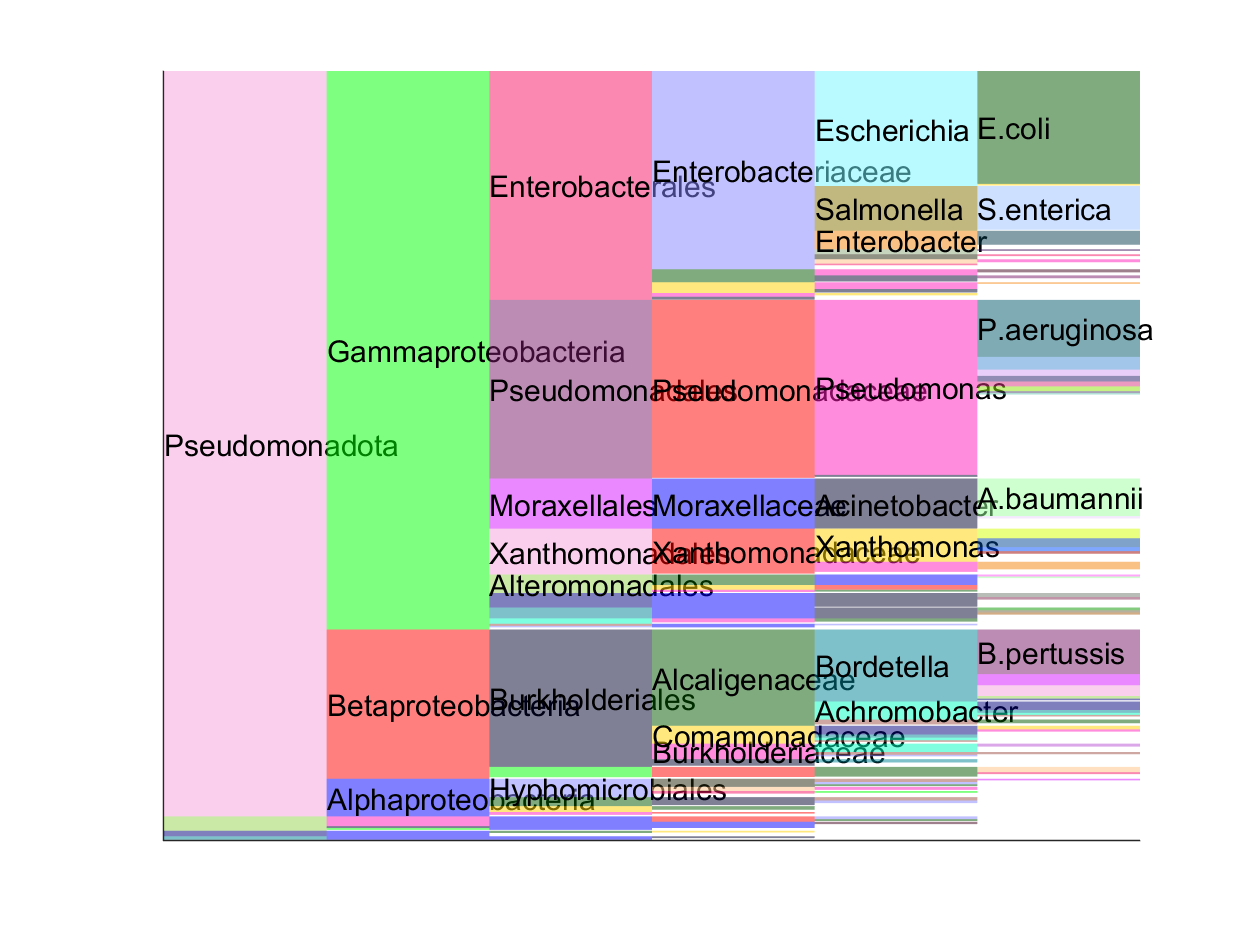

% distribution in bacteria
raw=importdata('./data/FpvA_in_bacteria.xlsx');
fpvAdata=raw.textdata.origin(2:end,:);
clear raw;

fpvA_columnid=[];
fpvA_columnid.acc=1;
fpvA_columnid.withsid=2;
fpvA_columnid.ispathogen=3;
fpvA_columnid.s_g=4;
fpvA_columnid.type=5;

fpvA_columnid.phylum=6;
fpvA_columnid.class=7;
fpvA_columnid.order=8;
fpvA_columnid.family=9;
fpvA_columnid.genus=10;
fpvA_columnid.species=11;

%distinguishable_colors(10,'w');

levels_unistr_counts=[];

phylo_id=zeros(size(fpvAdata,1),length(6:11));
clear levelinfor

for i=1:size(phylo_id,2)
    
    % assign each level an ID, that in descending order
    [uni_strs,~,ids]=unique(fpvAdata(:,i+5));
    % measure the counts of each class
    clear str_count;
    for j=1:length(uni_strs)
        str_count(j)=sum(ids==j);
    end
    [value,order]=sort(str_count);
    levelinfor(i).uni_strs=uni_strs(order);
    levelinfor(i).str_count=str_count(order);
    
    previoustonow=order;
    previoustonow(order)=1:length(order);
    phylo_id(:,i)=previoustonow(ids)';
end

% then, order all strains by their column ids
[uni_rows,~,strain_id_inunirow]=unique(phylo_id,'rows');

figure; hold on;
% ph=patch(1+6*[0 1 1 0],[0,0,1,1],[1,1,1]*0.8);ph.LineStyle='none';
toplotthresh=1/500;
textthreshold=1/50;
% plot them out by bars
for i=1:size(phylo_id,2)
    previouspercent=0;
    lastid=1;
    species_couont=0;
    
    
    for j=1:size(uni_rows,1)
        species_couont=species_couont+sum(strain_id_inunirow==j);
        % when it changes number
        if j==size(uni_rows,1)||(uni_rows(j+1,i)~= uni_rows(lastid,i))
            
            boxpercent=species_couont/size(strain_id_inunirow,1);
            
            if boxpercent>toplotthresh % plot out only under conditions
                if i==1
                    thislevelcount=14;
                    colorid=uni_rows(j,i);
                else
                    rows_sameprevious=find(uni_rows(:,i-1)==uni_rows(j,i-1));
                    % how many different current for these
                    [unicur,~,currentids]=unique(uni_rows(rows_sameprevious,i));
                    thislevelcount=max(currentids);
                    colorid=find(uni_rows(j,i)==unicur);
                end
                
                colortable=distinguishable_colors(thislevelcount);
                
                ph=patch(i+[0,1,1,0],previouspercent+boxpercent*[0,0,1,1],colortable(colorid,:));
                ph.LineStyle='none';
                ph.FaceAlpha=0.5;
                if boxpercent>textthreshold
                    strtoshow=levelinfor(i).uni_strs{uni_rows(lastid,i)};
                    strtoshow(1)=[];
                    strtoshow(end)=[];
                    if i==size(phylo_id,2)
                        strlist=strsplit(strtoshow);
                        strtoshow=[strlist{1}(1),'.',strlist{2}];
                    end
                    text(i,previouspercent+0.5*boxpercent,strtoshow);
                end
            end
            
            previouspercent=previouspercent+boxpercent;
            
            lastid=j+1;
            species_couont=0;
            % plot the last one, if it takes certain space
        end
        
        
    end
    previouspercent+boxpercent;
end
box off

ylim([0 1])
set(gca,'ytick',[],'xtick',[]);
box off